load('Samples_info.mat')
load('Test_data.mat')

Ocean_a = [0.17 0.37 0.45];
Ocean_b = [0.17 0.47 0.65];
Ocean_c = [0.27 0.37 0.55];

Olive_a = [0.73 0.79 0.00];
Olive_b = [0.63 0.89 0.40];
Olive_c = [0.63 0.79 0.70];

Ocean   = [0.17 0.47 0.45];
Olive   = [0.73 0.79 0.00];
Ash     = [0.16 0.34 0.20];
Berry   = [0.69 0.33 0.27]; 
Orange  = [0.94 0.43 0.13];
Canary  = [1.00 0.77 0.42];
River   = [0.18 0.51 0.43];

Clear previous workspace and command window and set colors

#### Do not forget to load sample data gathered from all experiments!

clc
%% Import data: Samples_info
% opts.VariableNames = ["Samples", "Method", "TestDate", "Weightkg", "MaxLoadN", "MaxDispmm", "TendonRsqmm", "MaxStressRMPa", "TendonEsqmm", "MaxStressEMPa"];
% opts.VariableTypes = ["char", "categorical", "datetime", "double", "double", "double", "double", "double", "double", "double"];

%% Import data: Gathered_data
% opts.VariableNames = ["B5o_Displacementmm", "B5o_LoadN", "B5o_Majormm", "B5o_minormm", "B7o_Displacementmm", "B7o_LoadN", "B7o_Majormm", "B7o_minormm", "B9o_Displacementmm", "B9o_LoadN", "B9o_Majormm", "B9o_minormm", "B1o_Displacementmm", "B1o_LoadN", "B1o_Majormm", "B1o_minormm", "B10o_Displacementmm", "B10o_LoadN", "B10o_Majormm", "B10o_minormm", "B11o_Displacementmm", "B11o_LoadN", "B11o_Majormm", "B11o_minormm", "B5n_Displacementmm", "B5n_LoadN", "B5n_Majormm", "B5n_minormm", "B6n_Displacementmm", "B6n_LoadN", "B6n_Majormm", "B6n_minormm", "B7n_Displacementmm", "B7n_LoadN", "B7n_Majormm", "B7n_minormm", "B9n_Displacementmm", "B9n_LoadN", "B9n_Majormm", "B9n_minormm", "B10n_Displacementmm", "B10n_LoadN", "B10n_Majormm", "B10n_minormm", "B11n_Displacementmm", "B11n_LoadN", "B11n_Majormm", "B11n_minormm"];
% opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

%For each sample we will have the following initial data
% B{i}o_Displacementmm 
% B{i}o_LoadN 
% B{i}o_Majormm
% B{i}o_minormm

%Colors
create_colours

# Single Sample Plots

#### Operated Samples | MSC

Plot the force vs. displacement graph of each sample on a different figure and from the slope of the Linear Region, calculate the stiffness of each sample. 

The maximum point of each graph corresponds to the failure force Ff and failure displacement Lf. 

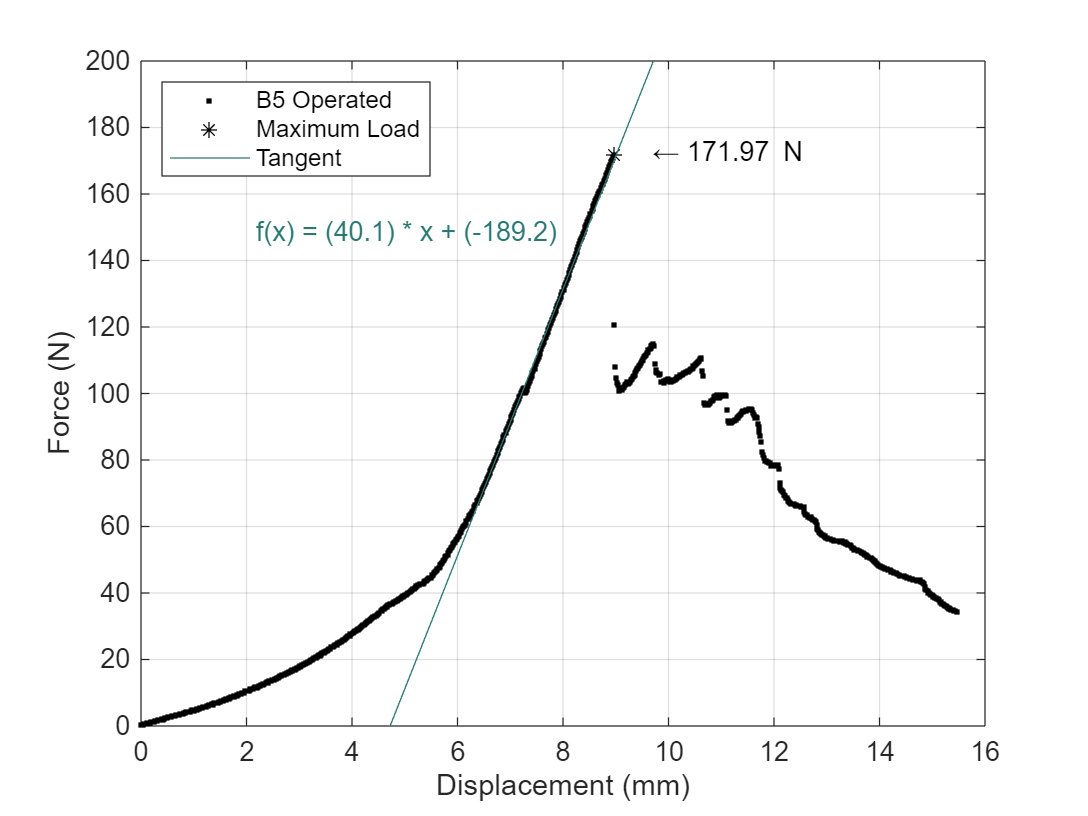

%%  'Operated with MSC Method'
% B5 Operated

figure( 'Name', 'B5 Operated' )

% Plot data
h = plot(B5o_Displacementmm, B5o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B5o_LoadN);
x_max          = B5o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'] )

% Plot tangent
x = 0:.1:20;
p = [40.07 -189.2]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,      polyval(p,x), 'Color', Ocean)
text(2.1712, 148.5046,  s, 'Color', Ocean)

% Legend
legend( 'B5 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 16]) 
ylim([0 200])
grid on

hold off

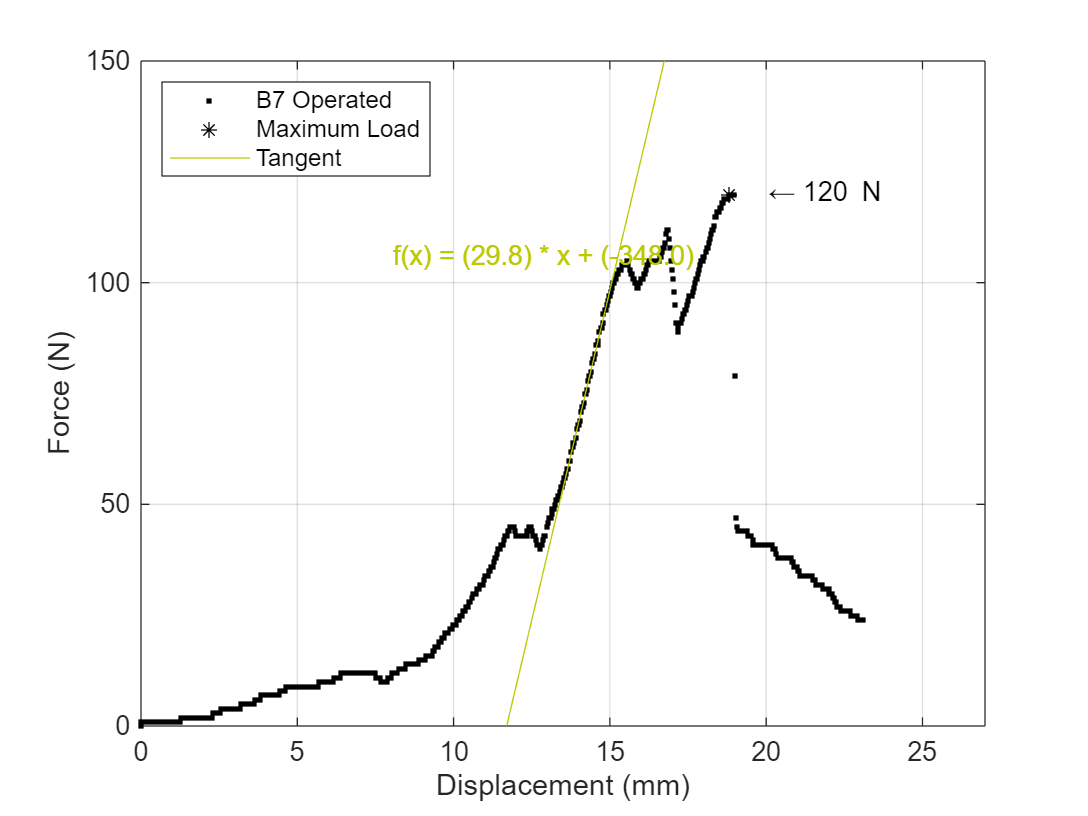


Stiffness_B5o =[p(1)];


% B7 Operated

figure( 'Name', 'B7 Operated' )

% Plot data
h = plot(B7o_Displacementmm, B7o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B7o_LoadN);
x_max          = B7o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max,  ['  \leftarrow', num2str(y_max), ' N'] )

% Plot tangent
% x = 0:.1:30;
% p = [16.38 -197.6]; % polynomial function
% s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
% plot(x,      polyval(p,x), 'Color', Ocean)
% text(4.1878, 56.0280,   s, 'Color', Ocean)

x = 0:.1:30;
l = [29.75 -348]; % polynomial function
z = sprintf('f(x) = (%.1f) * x + (%.1f)',l(1),l(2));
plot(x,      polyval(l,x), 'Color', Olive)
text(8.0662, 105.9813,  z, 'Color', Olive)

% Legend
legend( 'B7 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 27]) 
ylim([0 150])
grid on

hold off

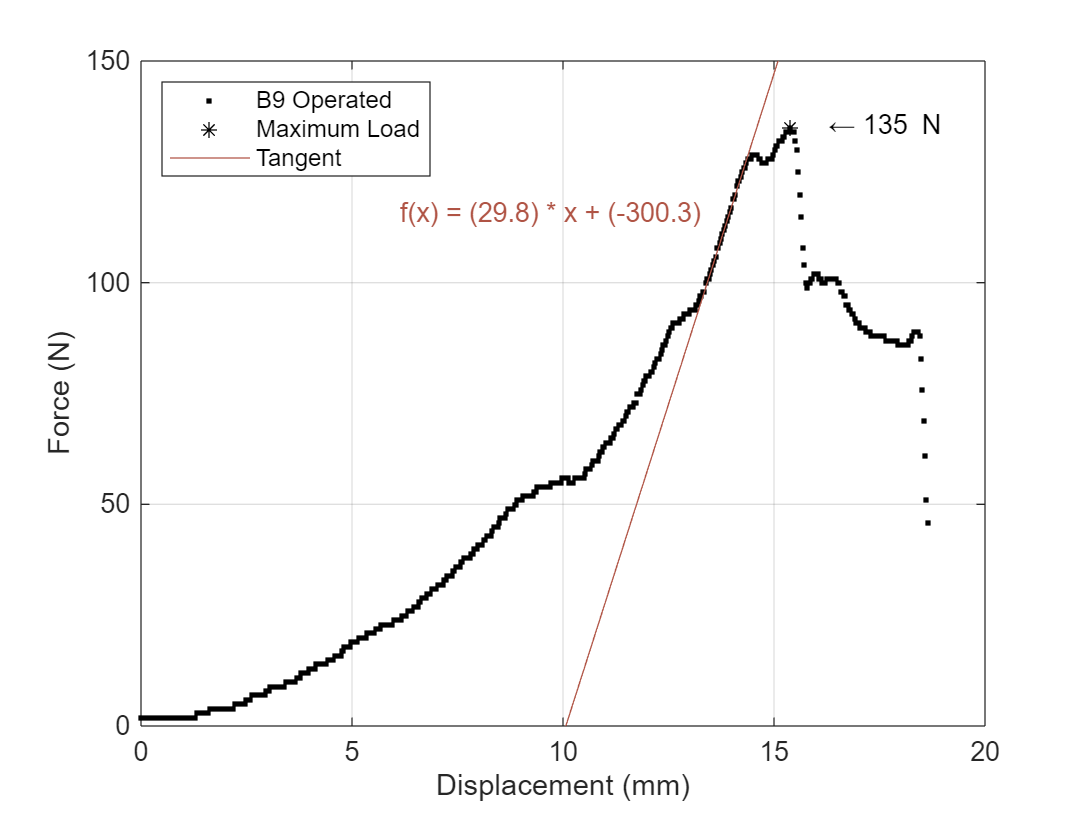


Stiffness_B7o =[l(1)];

% B9 Operated

figure( 'Name', 'B9 Operated' )

% Plot data
h = plot(B9o_Displacementmm, B9o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B9o_LoadN);
x_max          = B9o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'] )

% Plot tangent
% x = 0:.1:30;
% p = [10.09 -39.9]; % polynomial function
% s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
% plot(x,      polyval(p,x), 'Color', Ocean)
% text(0.8232, 44.8130,   s, 'Color', Ocean)

% x = 0:.1:30;
% u = [16.64 -121.1]; % polynomial function
% z = sprintf('f(x) = (%.1f) * x + (%.1f)',u(1),u(2));
% plot(x,      polyval(u,x), 'Color', Olive)
% text(3.9539, 81.0981,   z, 'Color', Olive)

x = 0:.1:30;
g = [29.83 -300.3]; % polynomial function
d = sprintf('f(x) = (%.1f) * x + (%.1f)',g(1),g(2));
plot(x,      polyval(g,x), 'Color', Berry)
text(6.1270, 115.6308,  d, 'Color', Berry)

% Legend
legend( 'B9 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 20]) 
ylim([0 150])
grid on


hold off


Stiffness_B9o =[g(1)];

From the slope of the Linear Region, we calculate the stiffness of each sample and the results are shown in the table created below.

Stiffness_MSC        = [Stiffness_B5o ; Stiffness_B7o ; Stiffness_B9o ];
Stiffness_MSC_mean   = mean(Stiffness_MSC);
Stiffness_MSC_std    = std(Stiffness_MSC);
Stiffness_MSC_median = median(Stiffness_MSC);
MSC_names           = ["B5 operated"; "B7 operated"; "B9 operated"];
Results_stif_MSC    = table(Stiffness_MSC,'RowNames',MSC_names)

Results_stif_MSC = 3×1 table
                   Stiffness_MSC
                   _____________

    B5 operated        40.07    
    B7 operated        29.75    
    B9 operated        29.83    


#### Operated Samples | TFL

Plot the force vs. displacement graph of each sample on a different figure and from the slope of the Linear Region, calculate the stiffness of each sample. 

The maximum point of each graph corresponds to the failure force Ff and failure displacement Lf. 

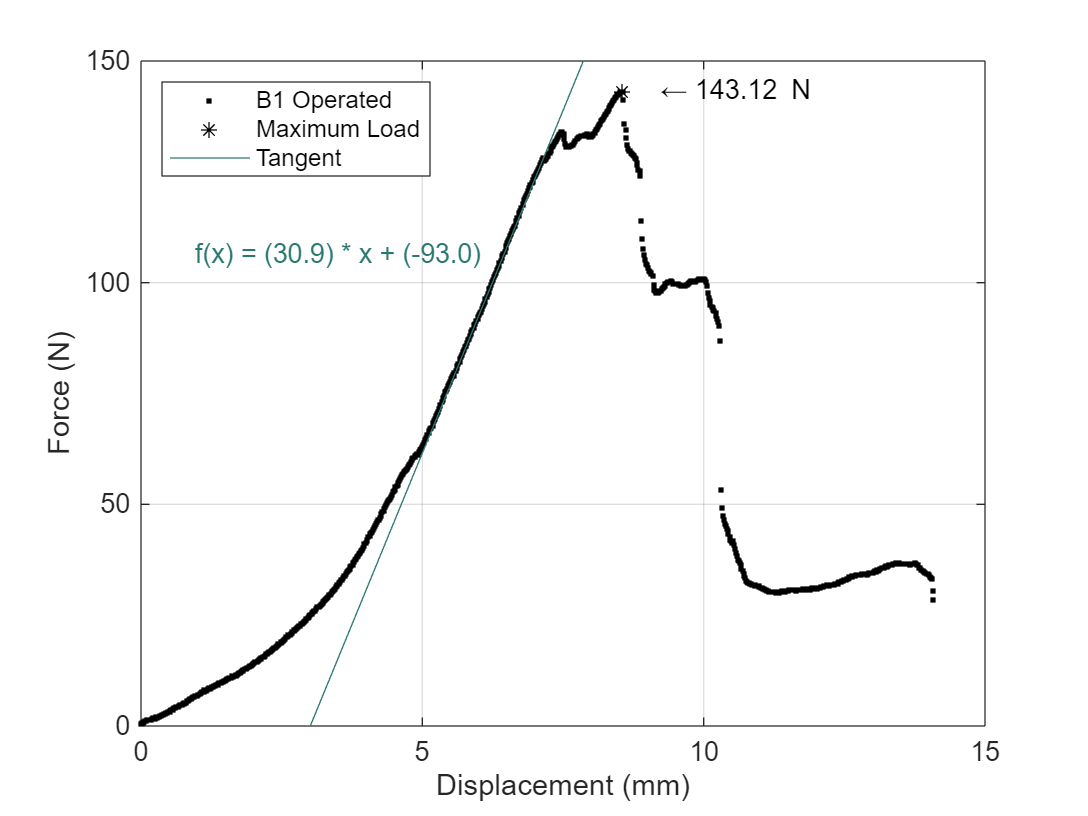

%%  'Operated with TFL Method'
% B1 Operated

figure( 'Name', 'B1 Operated' )

% Plot data
h = plot(B1o_Displacementmm, B1o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B1o_LoadN);
x_max          = B1o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [30.91 -92.99]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,      polyval(p,x), 'Color', Ocean)
text(0.9558, 106.4018,  s, 'Color', Ocean)

% Legend
legend( 'B1 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 15]) 
ylim([0 150])
grid on

hold off

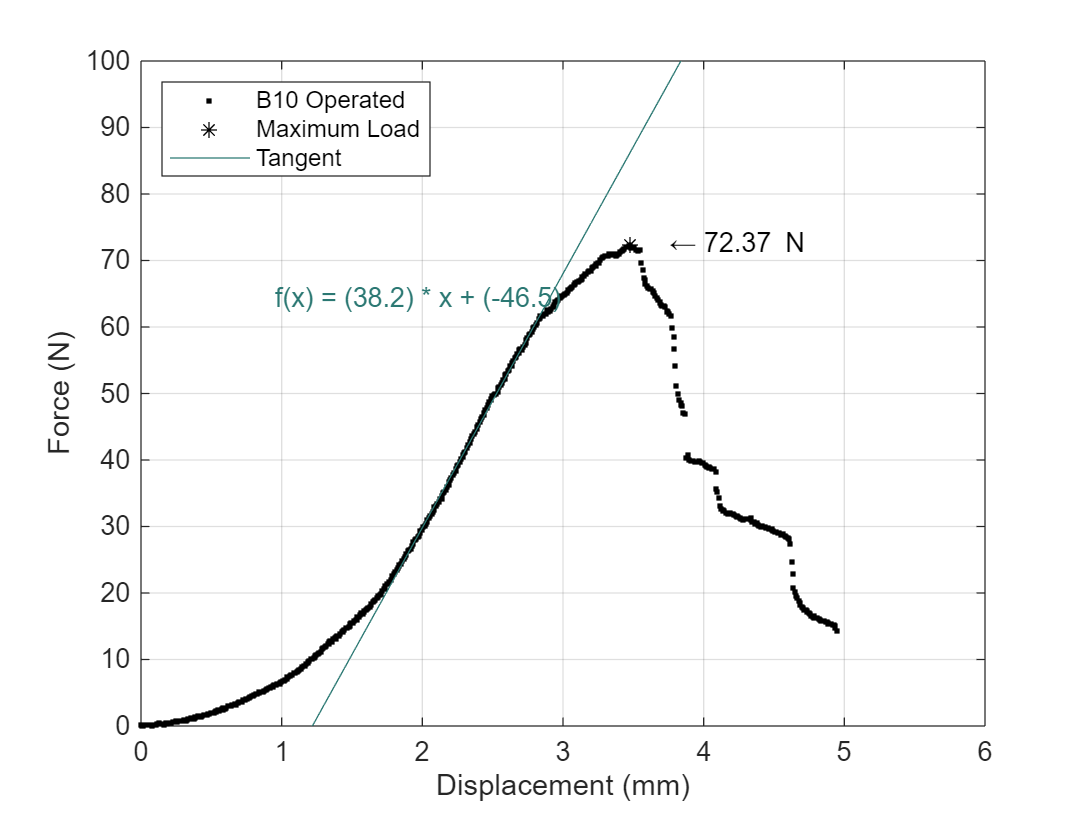


Stiffness_B1o =[p(1)];

% B10 Operated

figure( 'Name', 'B10 Operated' )

% Plot data
h = plot(B10o_Displacementmm, B10o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B10o_LoadN);
x_max          = B10o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [38.18 -46.52]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,      polyval(p,x), 'Color', Ocean)
text(0.9558, 64.4018,   s, 'Color', Ocean)

% Legend
legend( 'B10 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 6]) 
ylim([0 100])
grid on

hold off

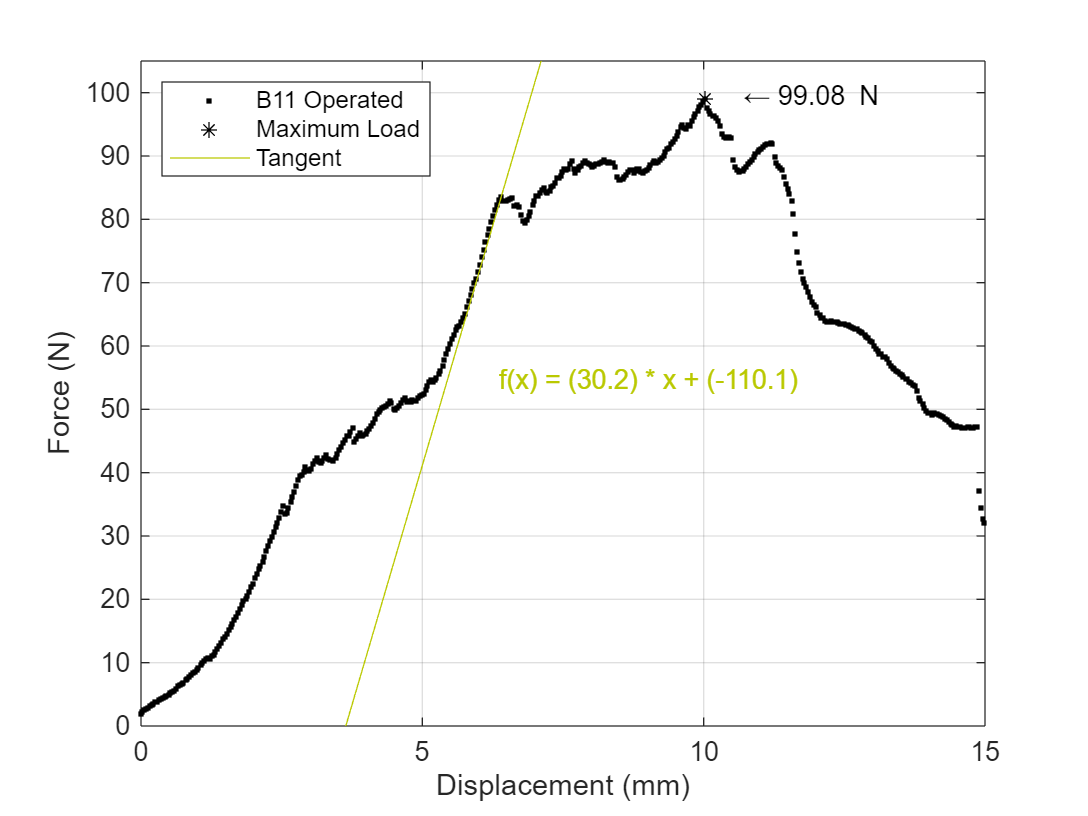


Stiffness_B10o =[p(1)];

% B11 Operated

figure( 'Name', 'B11 Operated' )

% Plot data
h = plot(B11o_Displacementmm, B11o_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B11o_LoadN);
x_max          = B11o_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max,['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
% x = 0:.1:17;
% p = [21.93 -21.86]; % polynomial function
% s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
% plot(x,      polyval(p,x), 'Color', Ocean)
% text(5.5580, 35.1985,   s, 'Color', Ocean)

x = 0:.1:17;
r = [30.25 -110.1]; % polynomial function
z = sprintf('f(x) = (%.1f) * x + (%.1f)',r(1),r(2));
plot(x,      polyval(r,x), 'Color', Olive)
text(6.3591, 54.6378,   z, 'Color', Olive)

% Legend
legend( 'B11 Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 15]) 
ylim([0 105])
grid on

hold off


Stiffness_B11o =[r(1)];

From the slope of the Linear Region, we calculate the stiffness of each sample and the results are shown in the table created below.

Stiffness_TFL        = [Stiffness_B1o ; Stiffness_B10o ; Stiffness_B11o ];
Stiffness_TFL_mean   = mean(Stiffness_TFL);
Stiffness_TFL_std    = std(Stiffness_TFL);
Stiffness_TFL_median = median(Stiffness_TFL);
TFL_names        = ["B1 operated"; "B10 operated"; "B11 operated"];
Results_stif_TFL = table(Stiffness_TFL,'RowNames',TFL_names)

Results_stif_TFL = 3×1 table
                    Stiffness_TFL
                    _____________

    B1 operated         30.91    
    B10 operated        38.18    
    B11 operated        30.25    


#### Non Operated Samples

Plot the force vs. displacement graph of each sample on a different figure and from the slope of the Linear Region, calculate the stiffness of each sample. 

The maximum point of each graph corresponds to the failure force Ff and failure displacement Lf. 

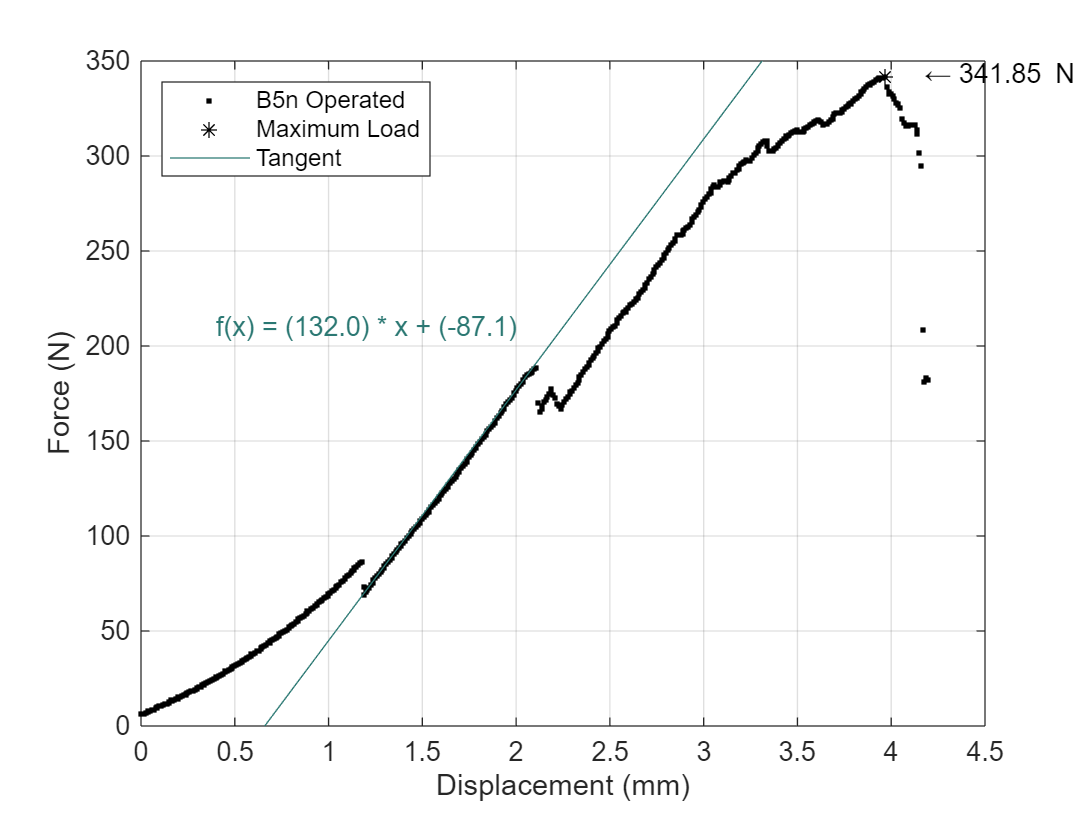

%%  'Non Operated'
% B5 Non Operated

figure( 'Name', 'B5 Non Operated' )

% Plot data
h = plot(B5n_Displacementmm, B5n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B5n_LoadN);
x_max          = B5n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [132 -87.08]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Ocean)
text(0.4, 210,       s, 'Color', Ocean)

% Legend
legend( 'B5n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );

xlim([0 4.5]) 
ylim([0 350])
grid on

hold off

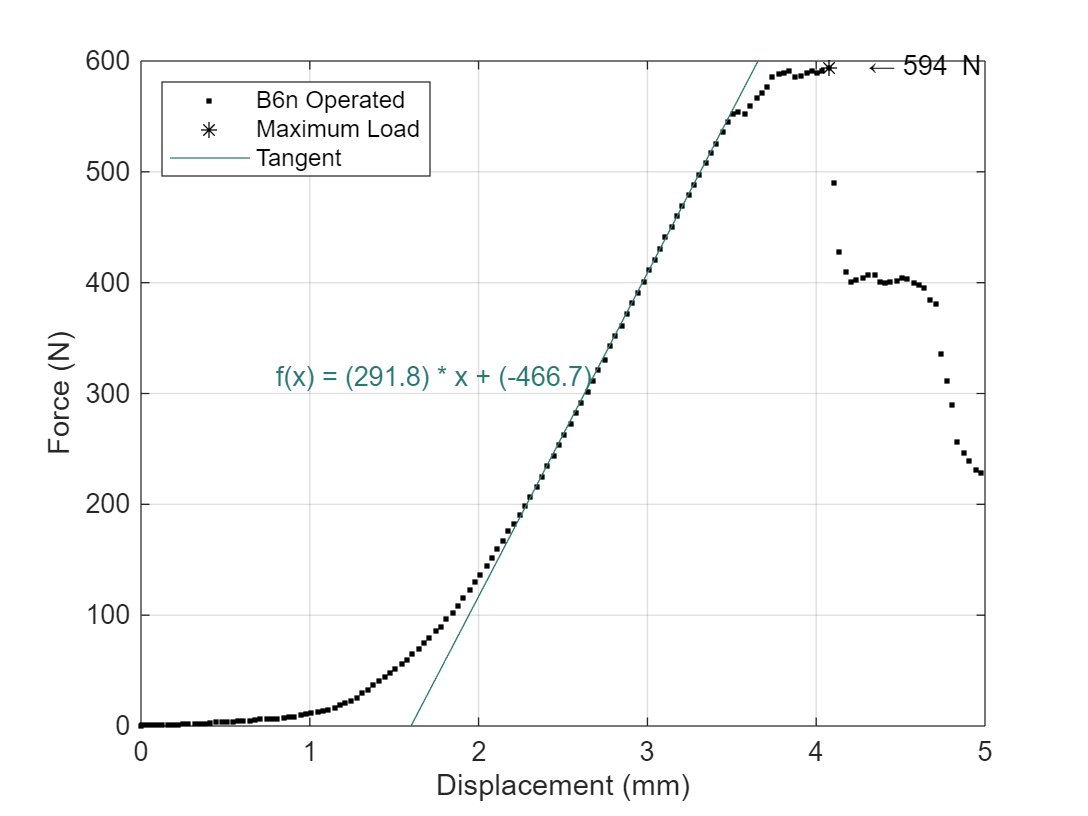


Stiffness_B5n =[p(1)];

% B6 Non Operated

figure( 'Name', 'B6 Non Operated' )

% Plot data
h = plot(B6n_Displacementmm, B6n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B6n_LoadN);
x_max          = B6n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [291.8 -466.7]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Ocean)
text(0.8, 315,       s, 'Color', Ocean)

% Legend
legend( 'B6n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 5]) 
ylim([0 600])
grid on

hold off

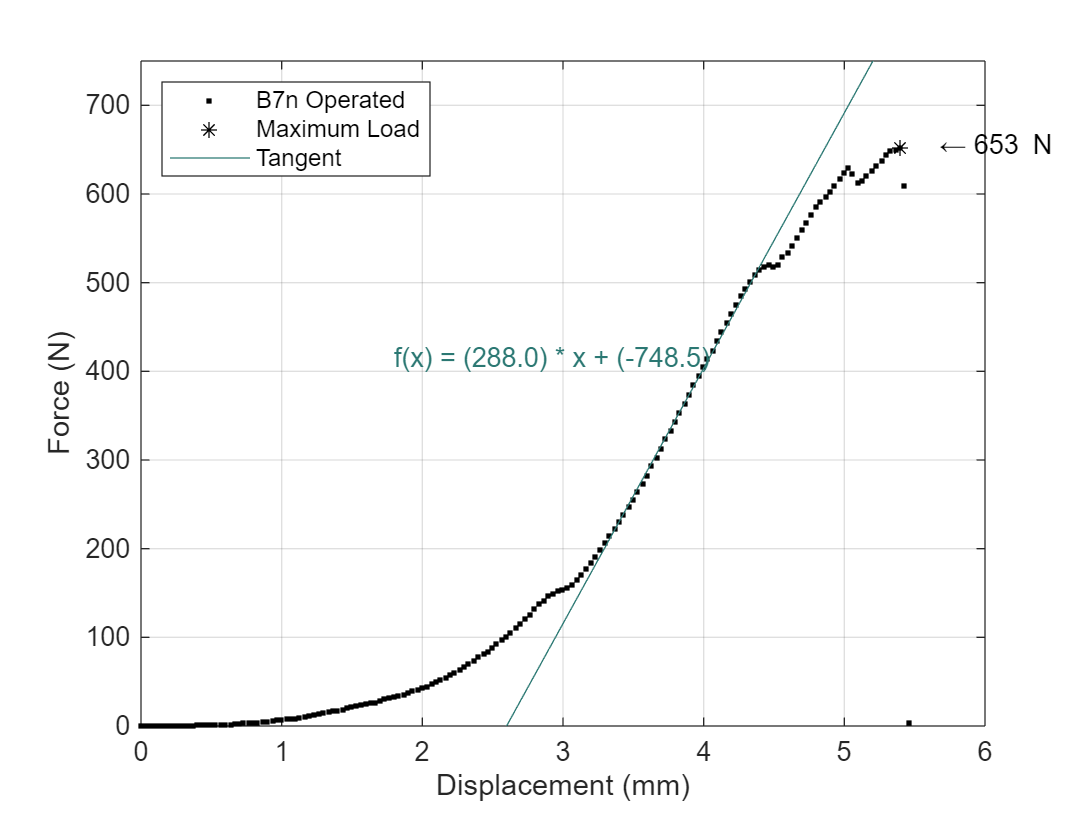


Stiffness_B6n =[p(1)];

% B7 Non Operated

figure( 'Name', 'B7 Non Operated' )

% Plot data
h = plot(B7n_Displacementmm, B7n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B7n_LoadN);
x_max          = B7n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [288 -748.5]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Ocean)
text(1.8, 415,       s, 'Color', Ocean)

% Legend
legend( 'B7n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 6]) 
ylim([0 750])
grid on

hold off

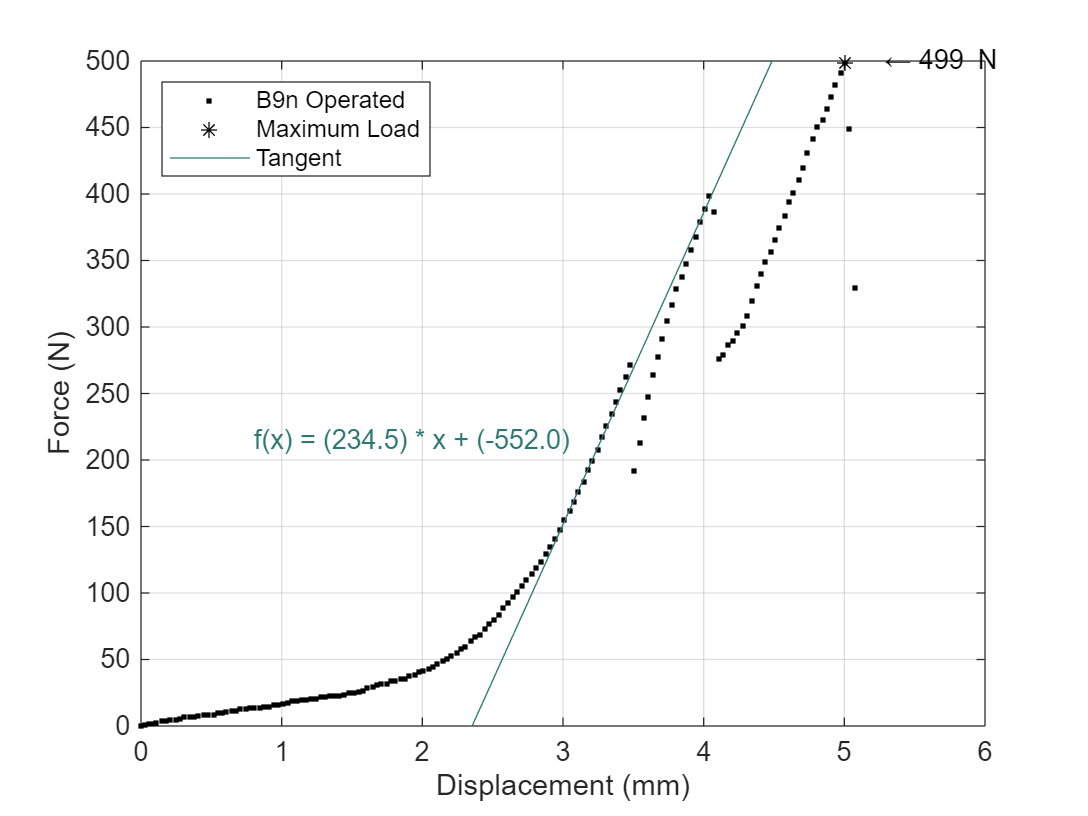


Stiffness_B7n =[p(1)];

% B9 Non Operated

figure( 'Name', 'B9 Non Operated' )

% Plot data
h = plot(B9n_Displacementmm, B9n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B9n_LoadN);
x_max          = B9n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p =[ 234.5 -552]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Ocean)
text(0.8, 215,       s, 'Color', Ocean)

% Legend
legend( 'B9n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 6]) 
ylim([0 500])
grid on

hold off

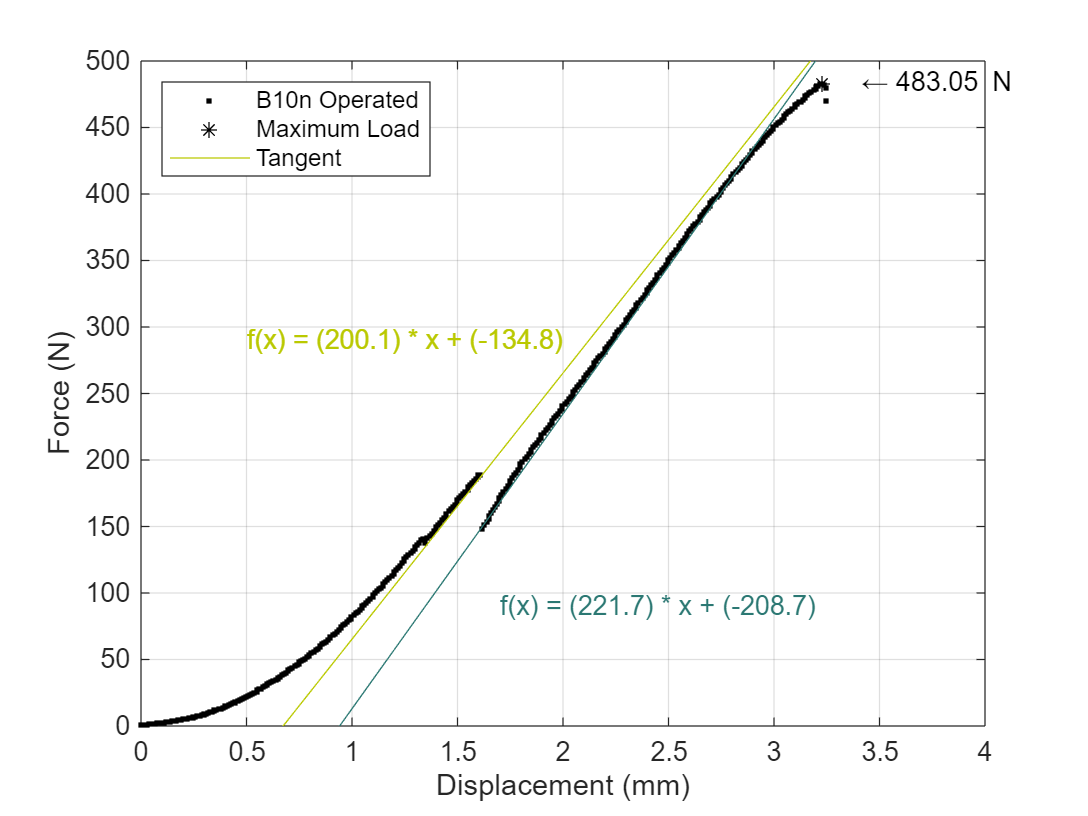


Stiffness_B9n =[p(1)];

% B10 Non Operated

figure( 'Name', 'B10 Non Operated' )

% Plot data
h = plot(B10n_Displacementmm, B10n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B10n_LoadN);
x_max          = B10n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [200.1 -134.8]; % polynomial function
z = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Olive)
text(0.5, 290,       z, 'Color', Olive)

x = 0:.1:17;
k = [221.7 -208.7]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',k(1),k(2));
plot(x,   polyval(k,x), 'Color', Ocean)
text(1.7, 90,        s, 'Color', Ocean)

% Legend
legend( 'B10n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 4]) 
ylim([0 500])
grid on

hold off

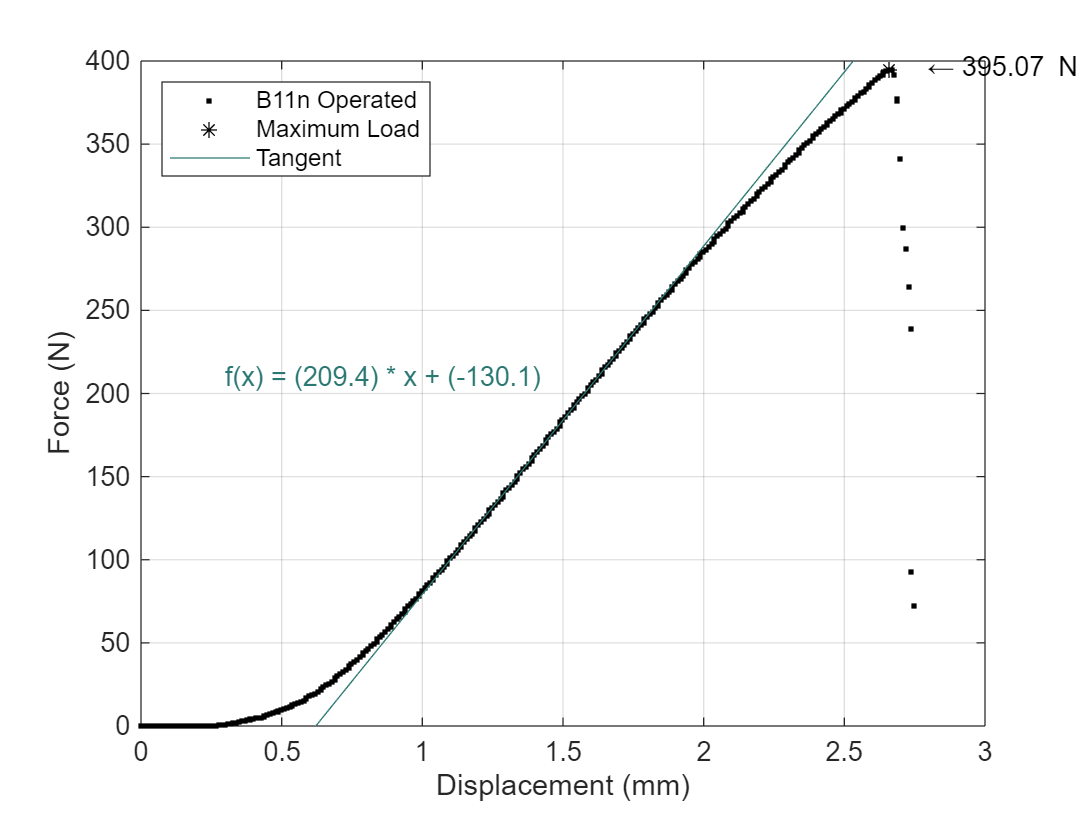


Stiffness_B10n = mean([p(1) k(1)]);

% B11 Non Operated

figure( 'Name', 'B11 Non Operated' )

% Plot data
h = plot(B11n_Displacementmm, B11n_LoadN,'k.' );

hold on

% Plot maximum point
[y_max, index] = max(B11n_LoadN);
x_max          = B11n_Displacementmm(index);
plot( x_max,  y_max, 'k*')
text( x_max,  y_max, ['  \leftarrow', num2str(y_max), ' N'])

% Plot tangent
x = 0:.1:17;
p = [209.4 -130.1]; % polynomial function
s = sprintf('f(x) = (%.1f) * x + (%.1f)',p(1),p(2));
plot(x,   polyval(p,x), 'Color', Ocean)
text(0.3 , 210,      s, 'Color', Ocean)

% Legend
legend( 'B11n Operated','Maximum Load','Tangent', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)',         'Interpreter', 'none' );
xlim([0 3]) 
ylim([0 400])
grid on

hold off


Stiffness_B11n =[p(1)];

From the slope of the Linear Region, we calculate the stiffness of each sample and the results are shown in the table created below.

Stiffness_non        = [Stiffness_B5n ; Stiffness_B6n ; Stiffness_B7n; Stiffness_B9n ; Stiffness_B10n ; Stiffness_B11n];
Stiffness_non_mean   = mean(Stiffness_non);
Stiffness_non_std    = std(Stiffness_non);
Stiffness_non_median = median(Stiffness_non);
non_names        = ["B5 non operated"; "B6 non operated"; "B7 non operated"; "B9 Non operated"; "B10 Non operated"; "B11 Non operated"];
Results_stif_Non = table(non_names, Stiffness_non)

Results_stif_Non = 6×2 table
        non_names         Stiffness_non
    __________________    _____________

    "B5 non operated"           132    
    "B6 non operated"         291.8    
    "B7 non operated"           288    
    "B9 Non operated"         234.5    
    "B10 Non operated"        210.9    
    "B11 Non operated"        209.4    


# Comparative sample plots

Plot the force vs. displacement graph on group figures for comparison of the mechanical behaviour of each sample. 

%Every group on one graph for comparison

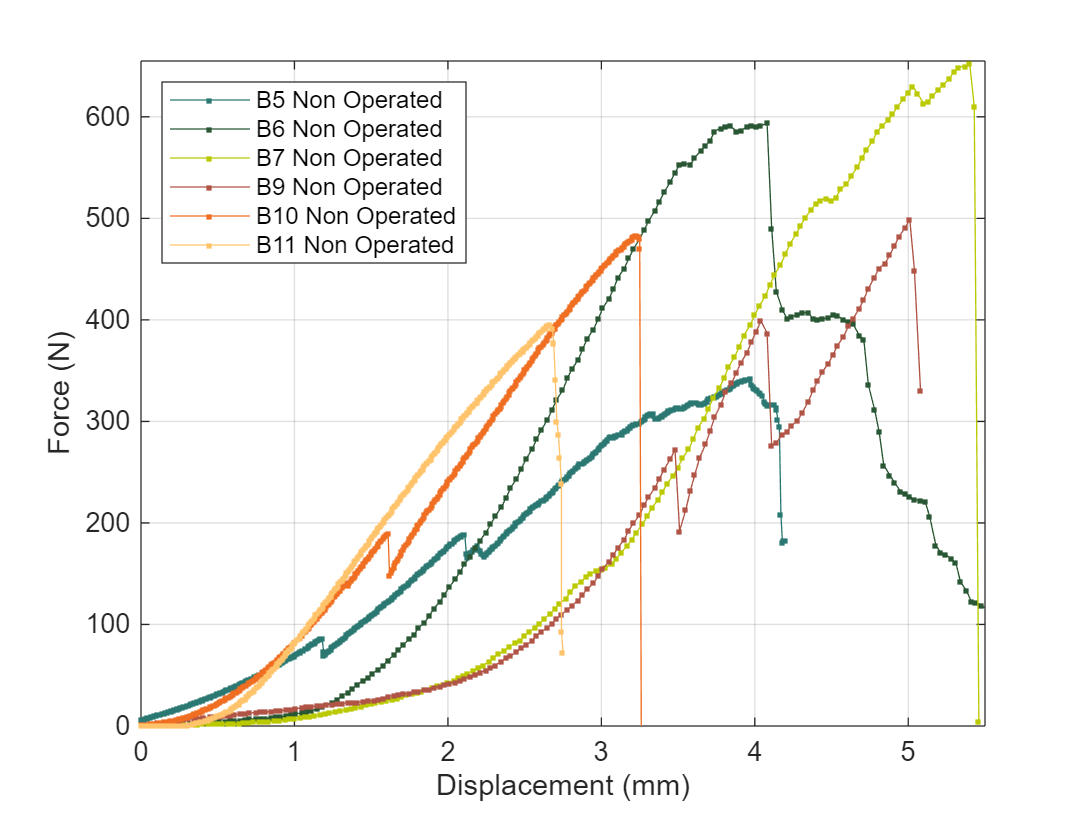

%%  'Non Operated'
figure( 'Name', 'Non Operated | Compared' )
title("Non operated samples")

% Plot data
h = plot(B5n_Displacementmm,  B5n_LoadN, 'Marker','.','LineStyle','-','color', Ocean ); % B5 Non Operated Ocean = [0.18 0.51 0.43];

hold on

h = plot(B6n_Displacementmm,  B6n_LoadN, 'Marker','.','LineStyle','-','color', Ash    ); % B6 Non Operated 

h = plot(B7n_Displacementmm,  B7n_LoadN, 'Marker','.','LineStyle','-','color', Olive  ); % B7 Non Operated 

h = plot(B9n_Displacementmm,  B9n_LoadN, 'Marker','.','LineStyle','-','color', Berry  ); % B9 Non Operated 

h = plot(B10n_Displacementmm, B10n_LoadN,'Marker','.','LineStyle','-','color', Orange ); % B10 Non Operated 

h = plot(B11n_Displacementmm, B11n_LoadN,'Marker','.','LineStyle','-','color', Canary ); % B11 Non Operated 

% Legend
legend( 'B5 Non Operated','B6 Non Operated','B7 Non Operated','B9 Non Operated','B10 Non Operated','B11 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)', 'Interpreter', 'none' );
grid on
xlim([0 5.5]) 
ylim([0 655])

hold off

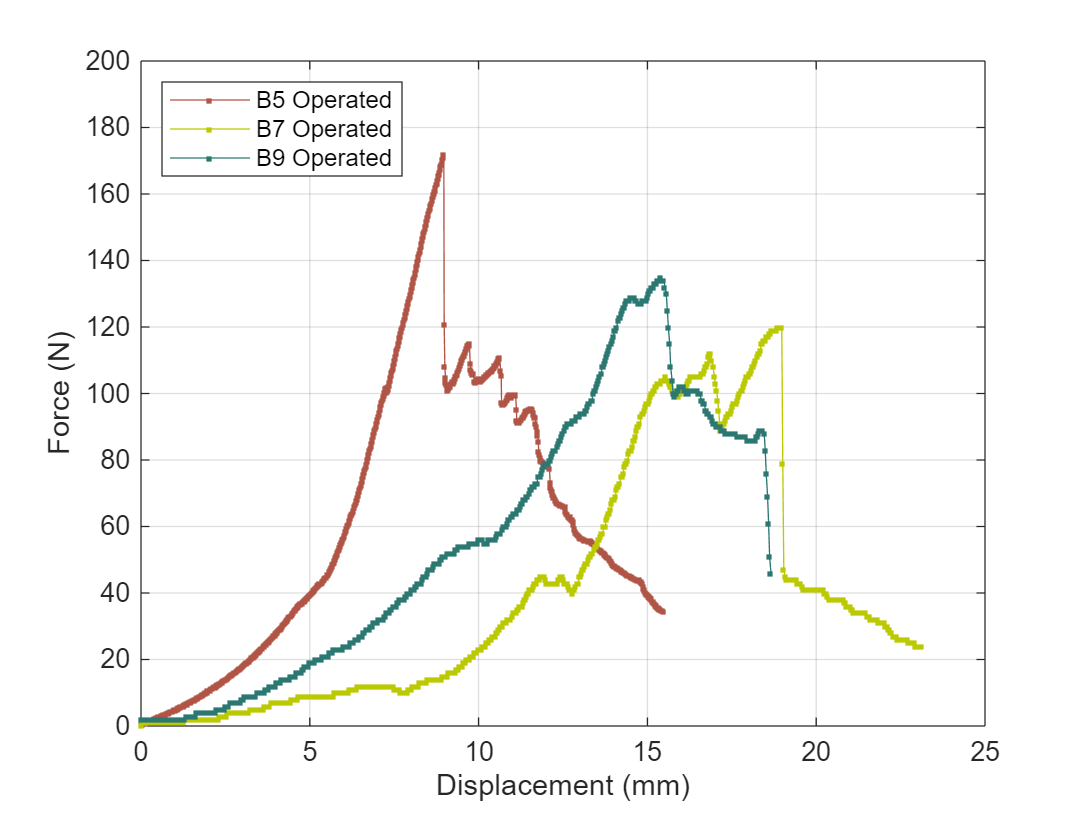

%%  'Operated with MSC Method'
figure( 'Name', 'Operated  with MSC Method | Compared' )
title("Operated samples with MSC Method")

% Plot data
h = plot(B5o_Displacementmm, B5o_LoadN,'Marker','.','LineStyle','-','color', Berry ); % B5 Operated

hold on

h = plot(B7o_Displacementmm, B7o_LoadN,'Marker','.','LineStyle','-','color', Olive ); % B7 Operated

h = plot(B9o_Displacementmm, B9o_LoadN,'Marker','.','LineStyle','-','color', Ocean ); % B9 Operated

% Legend
legend( 'B5 Operated','B7 Operated','B9 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)', 'Interpreter', 'none' );
grid on
xlim([0 25]) 
ylim([0 200])

hold off

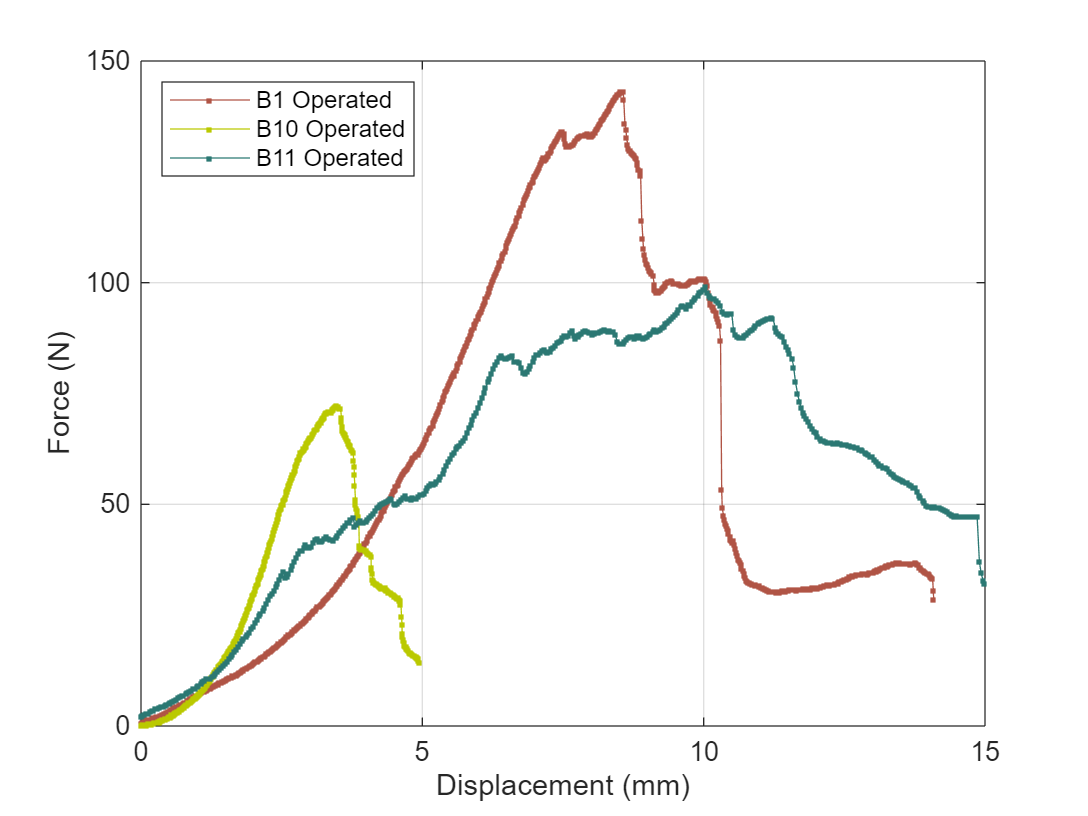

%%  'Operated with TFL Method'
figure( 'Name', 'Operated with TFL Method | Compared' )
title("Operated samples with TFL Method")

% Plot data
h = plot(B1o_Displacementmm,  B1o_LoadN, 'Marker','.','LineStyle','-','color', Berry ); % B1 Operated

hold on

h = plot(B10o_Displacementmm, B10o_LoadN,'Marker','.','LineStyle','-','color', Olive ); % B10 Operated

h = plot(B11o_Displacementmm, B11o_LoadN,'Marker','.','LineStyle','-','color', Ocean ); % B11 Operated

% Legend
legend( 'B1 Operated','B10 Operated','B11 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)', 'Interpreter', 'none' );
grid on
xlim([0 15]) 
ylim([0 150])

hold off 

%Plots for comparison

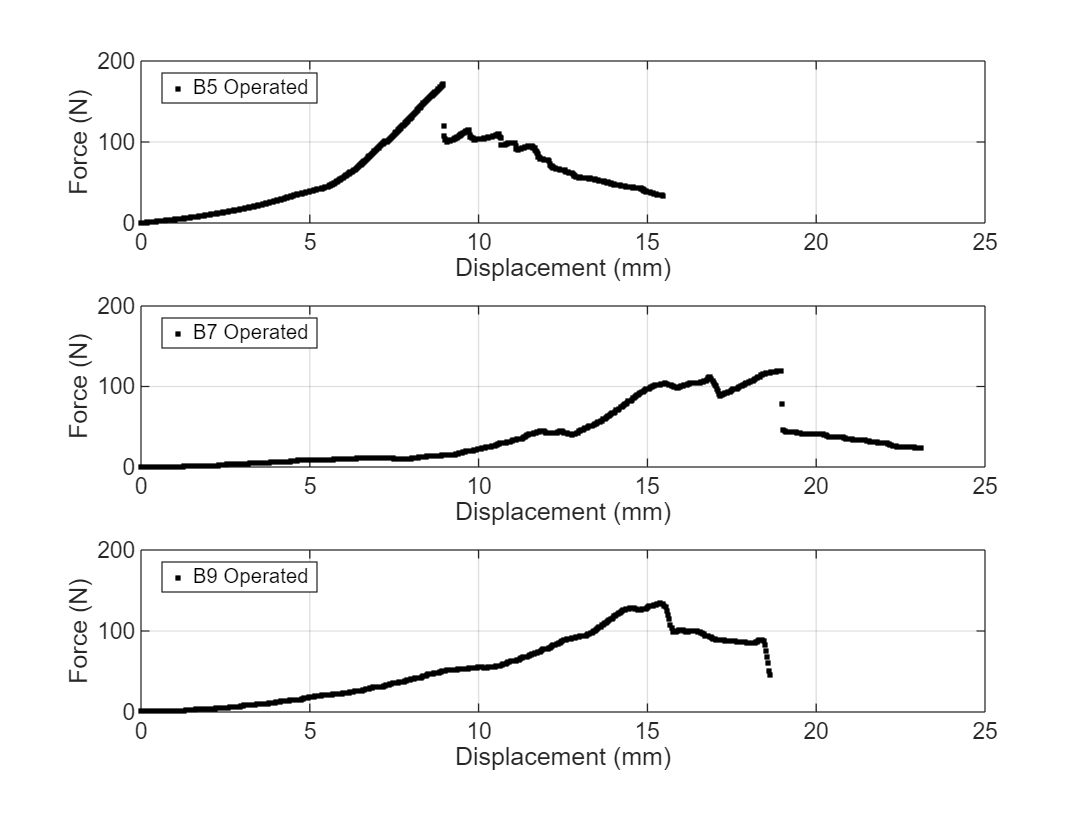

%%  'Operated with MSC Method'
figure( 'Name', 'Operated  with MSC Method' )
title("Operated samples with MSC Method")

    subplot(3,1,1);
    title('B5 Operated')
    
        % Plot data
        h = plot(B5o_Displacementmm, B5o_LoadN,'k.' );
        
        % Legend
        legend( 'B5 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 25]) 
        ylim([0 200])

    subplot(3,1,2);
    title('B7 Operated')
    
        % Plot data
        h = plot(B7o_Displacementmm, B7o_LoadN,'k.' );
        
        % Legend
        legend( 'B7 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 25]) 
        ylim([0 200])

    subplot(3,1,3);
    title('B9 Operated')
        
        % Plot data
        h = plot(B9o_Displacementmm, B9o_LoadN,'k.' );
        
        % Legend
        legend( 'B9 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 25]) 
        ylim([0 200])

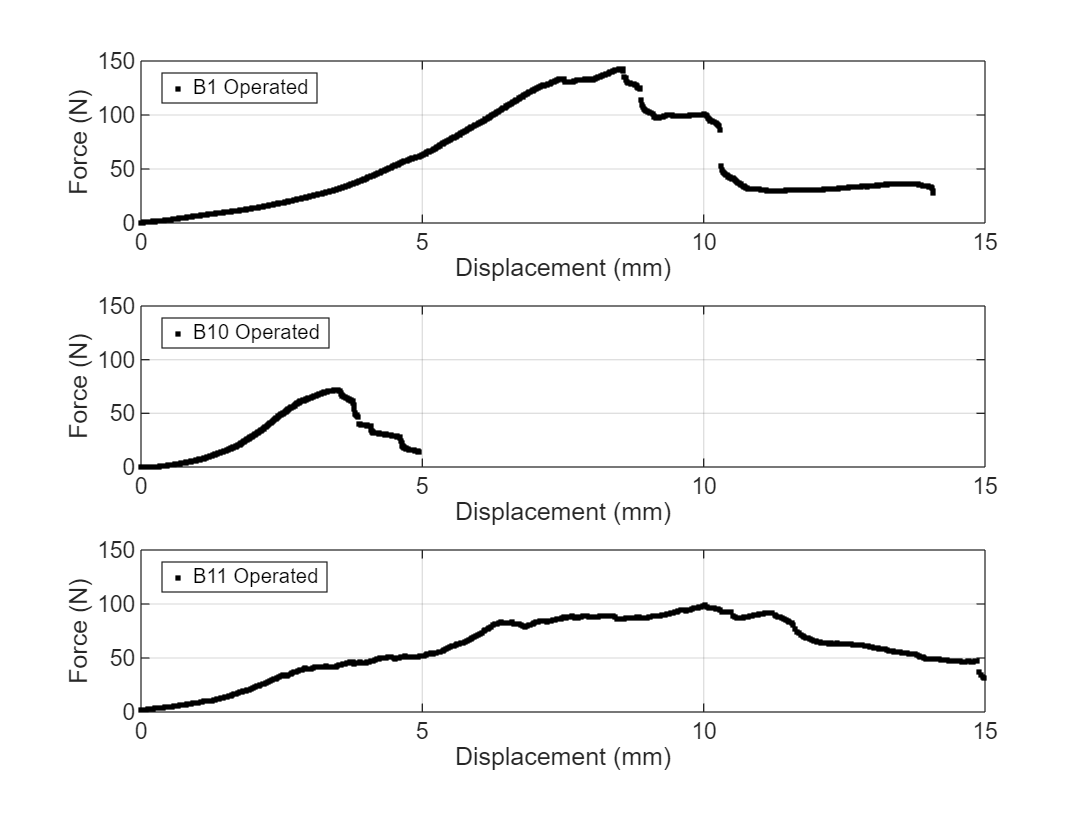

%%  'Operated with TFL Method'
figure( 'Name', 'Operated with TFL Method' )
title("Operated samples with TFL Method")
    
    subplot(3,1,1);
    title('B1 Operated')
    
        % Plot data
        h = plot(B1o_Displacementmm, B1o_LoadN,'k.' );
        
        % Legend
        legend( 'B1 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 15]) 
        ylim([0 150])
   
    subplot(3,1,2);
    title('B10 Operated')
    
        % Plot data
        h = plot(B10o_Displacementmm, B10o_LoadN,'k.' );
        
        % Legend
        legend( 'B10 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 15]) 
        ylim([0 150])
    
    subplot(3,1,3);
    title('B11 Operated')
    
        % Plot data
        h = plot(B11o_Displacementmm, B11o_LoadN,'k.' );
        
        % Legend
        legend( 'B11 Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 15]) 
        ylim([0 150])

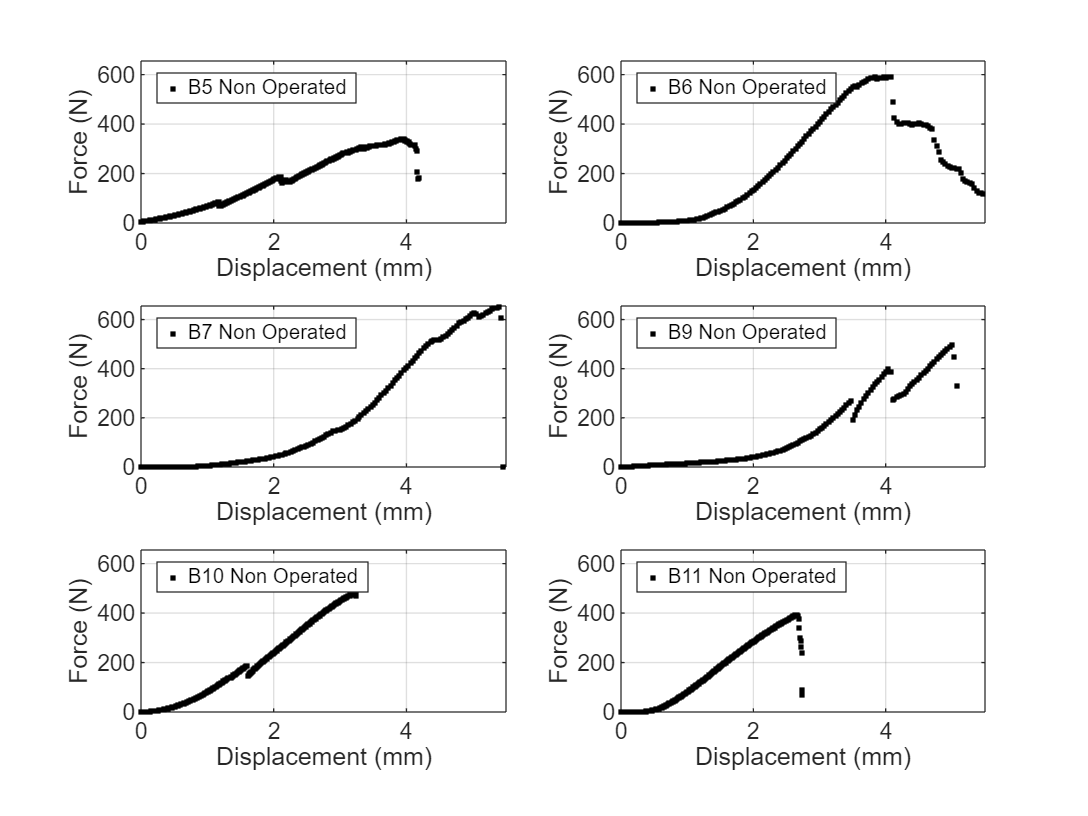

%%  'Non Operated'
figure( 'Name', 'Non Operated' )
title("Non operated samples")

    subplot(3,2,1);
    title('B5 Non Operated')
    
        % Plot data
        h = plot(B5n_Displacementmm, B5n_LoadN,'k.' );
        
        % Legend
        legend( 'B5 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])
    
    subplot(3,2,2);
    title('B6 Non Operated')
    
        % Plot data
        h = plot(B6n_Displacementmm, B6n_LoadN,'k.' );
        
        % Legend
        legend( 'B6 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])
    
    subplot(3,2,3);
    title('B7 Non Operated')
    
        % Plot data
        h = plot(B7n_Displacementmm, B7n_LoadN,'k.' );
        
        %Legend
        legend( 'B7 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])
    
    subplot(3,2,4);
    title('B9 Non Operated')
    
        % Plot data
        h = plot(B9n_Displacementmm, B9n_LoadN,'k.' );
        
        % Legend
        legend( 'B9 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])
    
    subplot(3,2,5);
    title('B10 Non Operated')
    
        % Plot data
        h = plot(B10n_Displacementmm, B10n_LoadN,'k.' );
        
        % Legend
        legend( 'B10 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])
    
    subplot(3,2,6);
    title('B11 NonOperated')
    
        % Plot data
        h = plot(B11n_Displacementmm, B11n_LoadN,'k.' );
        
        % Legend
        legend( 'B11 Non Operated', 'Location', 'NorthWest', 'Interpreter', 'none' );
        
        % Label axes
        xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
        ylabel( 'Force (N)', 'Interpreter', 'none' );
        grid on
        xlim([0 5.5]) 
        ylim([0 655])

# Experimental Results

%% Create a Table for all samples initial information
Names = categorical(Samples);
T     = table(Names, Method, TestDate, Weightkg, MaxDispmm, MaxLoadN,TendonRsqmm, MaxStressRMPa, TendonEsqmm, MaxStressEMPa,'RowNames',Samples);
%format compact
summary(T);


T: 12×10 table

Variables:

    Names: categorical (12 categories)
    Method: categorical (3 categories)
    TestDate: datetime
    Weightkg: double
    MaxDispmm: double
    MaxLoadN: double
    TendonRsqmm: double
    MaxStressRMPa: do


Failure_load_all        = table2array(T(:,"MaxLoadN"));
Failure_load_all_mean   = mean(Failure_load_all);
Failure_load_all_std    = std(Failure_load_all);
Failure_load_all_median = median(Failure_load_all);

Disp_max_all            = table2array(T(:,"MaxDispmm"));
Disp_max_all_mean       = mean(Disp_max_all);
Disp_max_all_std        = std(Disp_max_all);
Disp_max_all_median     = median(Disp_max_all);

Max_Stress_Ellipsis_all      = table2array(T(:,"MaxStressEMPa"));
Max_Stress_Ellips_all_mean   = mean(Max_Stress_Ellipsis_all);
Max_Stress_Ellips_all_std    = std(Max_Stress_Ellipsis_all);
Max_Stress_Ellips_all_median = median(Max_Stress_Ellipsis_all);

Max_Stress_Rectangle_all     = table2array(T(:,"MaxStressRMPa"));
Max_Stress_Rect_all_mean     = mean(Max_Stress_Rectangle_all);
Max_Stress_Rect_all_std      = std(Max_Stress_Rectangle_all);
Max_Stress_Rect_all_median   = std(Max_Stress_Rectangle_all);


#### Select Data Based on Categories | Non Operated

Create a subtable, `T1`, containing the names, maximum stress, and maxium load of all samples who were not operated and were used for an biomechanical experiment. 

%% Select Data Based on Categories | Non Operated
rows = T.Method=='Non';
vars = ["Names","MaxDispmm","MaxLoadN","MaxStressEMPa","MaxStressRMPa"];
T1   = T(rows,vars);
% format compact
% summary(T1);


Failure_load_non        = table2array(T1(:,"MaxLoadN"));
Failure_load_non_mean   = mean(Failure_load_non);
Failure_load_non_std    = std(Failure_load_non);
Failure_load_non_median = median(Failure_load_non);

Disp_max_non            = table2array(T1(:,"MaxDispmm"));
Disp_max_non_mean       = mean(Disp_max_non);
Disp_max_non_std        = std(Disp_max_non);
Disp_max_non_median     = median(Disp_max_non);

Max_Stress_Ellipsis_non      = table2array(T1(:,"MaxStressEMPa"));
Max_Stress_Ellips_non_mean   = mean(Max_Stress_Ellipsis_non);
Max_Stress_Ellips_non_std    = std(Max_Stress_Ellipsis_non);
Max_Stress_Ellips_non_median = median(Max_Stress_Ellipsis_non);

Max_Stress_Rectangle_non    = table2array(T1(:,"MaxStressRMPa"));
Max_Stress_Rect_non_mean   = mean(Max_Stress_Rectangle_non);
Max_Stress_Rect_non_std    = std(Max_Stress_Rectangle_non);
Max_Stress_Rect_non_median = std(Max_Stress_Rectangle_non);

Stiffness_non        = [Stiffness_B5n ; Stiffness_B6n ; Stiffness_B7n; Stiffness_B9n ; Stiffness_B10n ; Stiffness_B11n];
Stiffness_non_mean   = mean(Stiffness_non);
Stiffness_non_std    = std(Stiffness_non);
Stiffness_non_median = median(Stiffness_non);

#### Select Data Based on Categories | MSC

Create a subtable, `T2`, containing the names, maximum stress, and maxium load of all samples who were operated with the MSC method and were used for an biomechanical experiment. We define the subset of variables and use parentheses to create the subtable, `T2.`

%% Select Data Based on Categories | MSC
rows = T.Method=='MSC';
vars = ["Names","MaxDispmm","MaxLoadN","MaxStressEMPa","MaxStressRMPa"];
T2 = T(rows,vars);
% summary(T2);


Failure_load_MSC        = table2array(T2(:,"MaxLoadN"));
Failure_load_MSC_mean   = mean(Failure_load_MSC);
Failure_load_MSC_std    = std(Failure_load_MSC);
Failure_load_MSC_median = median(Failure_load_MSC);

Disp_max_MSC            = table2array(T2(:,"MaxDispmm"));
Disp_max_MSC_mean       = mean(Disp_max_MSC);
Disp_max_MSC_std        = std(Disp_max_MSC);
Disp_max_MSC_median     = median(Disp_max_MSC);

Max_Stress_Ellipsis_MSC      = table2array(T2(:,"MaxStressEMPa"));
Max_Stress_Ellips_MSC_mean   = mean(Max_Stress_Ellipsis_MSC);
Max_Stress_Ellips_MSC_std    = std(Max_Stress_Ellipsis_MSC);
Max_Stress_Ellips_MSC_median = median(Max_Stress_Ellipsis_MSC);

Max_Stress_Rectangle_MSC     = table2array(T2(:,"MaxStressRMPa"));
Max_Stress_Rect_MSC_mean     = mean(Max_Stress_Rectangle_MSC);
Max_Stress_Rect_MSC_std      = std(Max_Stress_Rectangle_MSC);
Max_Stress_Rect_MSC_median   = std(Max_Stress_Rectangle_MSC);

Stiffness_MSC        = [Stiffness_B5o ; Stiffness_B7o ; Stiffness_B9o ];
Stiffness_MSC_mean   = mean(Stiffness_MSC);
Stiffness_MSC_std    = std(Stiffness_MSC);
Stiffness_MSC_median = median(Stiffness_MSC);


#### Select Data Based on Categories | TFL

Create a subtable, `T3`, containing the names, maximum stress, and maxium load of all samples who were operated with the TFL method and were used for an biomechanical experiment. We define the subset of variables and use parentheses to create the subtable, `T3.`

%% Select Data Based on Categories | TFL
rows = T.Method=='FL';
vars = ["Names","MaxDispmm","MaxLoadN","MaxStressEMPa","MaxStressRMPa"];
T3 = T(rows,vars);
% summary(T3);


Failure_load_TFL        = table2array(T3(:,"MaxLoadN"));
Failure_load_TFL_mean   = mean(Failure_load_TFL);
Failure_load_TFL_std    = std(Failure_load_TFL);
Failure_load_TFL_median = median(Failure_load_TFL);

Disp_max_TFL            = table2array(T3(:,"MaxDispmm"));
Disp_max_TFL_mean       = mean(Disp_max_TFL);
Disp_max_TFL_std        = std(Disp_max_TFL); 
Disp_max_TFL_median     = median(Disp_max_TFL);

Max_Stress_Ellipsis_TFL      = table2array(T3(:,"MaxStressEMPa"));
Max_Stress_Ellips_TFL_mean   = mean(Max_Stress_Ellipsis_TFL);
Max_Stress_Ellips_TFL_std    = std(Max_Stress_Ellipsis_TFL);
Max_Stress_Ellips_TFL_median = median(Max_Stress_Ellipsis_TFL);

Max_Stress_Rectangle_TFL     = table2array(T3(:,"MaxStressRMPa"));
Max_Stress_Rect_TFL_mean     = mean(Max_Stress_Rectangle_TFL);
Max_Stress_Rect_TFL_std      = std(Max_Stress_Rectangle_TFL);
Max_Stress_Rect_TFL_median   = std(Max_Stress_Rectangle_TFL);

Stiffness_TFL        = [Stiffness_B1o ; Stiffness_B10o ; Stiffness_B11o ];
Stiffness_TFL_mean   = mean(Stiffness_TFL);
Stiffness_TFL_std    = std(Stiffness_TFL);
Stiffness_TFL_median = median(Stiffness_TFL);


## Results

We present the gathered results of each group in a table showing the mean, standard deviation and median of Failure Load, Displacement and Stiffness.

%% Gathered Results
Groups            = ["Non | Mean";                "Non | SD";                  "Non | Median";                  "MSC | Mean";                 "MSC | SD";                  "MSC | Median";                 "TFL | Mean";                 "TFL | SD";                  "TFL | Median"  ];
FailureLoad_N    = [Failure_load_non_mean;      Failure_load_non_std;      Failure_load_non_median;      Failure_load_MSC_mean;      Failure_load_MSC_std;      Failure_load_MSC_median;      Failure_load_TFL_mean;      Failure_load_TFL_std;      Failure_load_TFL_median     ];
Displacement_mm   = [Disp_max_non_mean;          Disp_max_non_std;          Disp_max_non_median;          Disp_max_MSC_mean;          Disp_max_MSC_std;          Disp_max_MSC_median;          Disp_max_TFL_mean;          Disp_max_TFL_std;          Disp_max_TFL_median         ];
Max_Stress_R_MPa  = [Max_Stress_Rect_non_mean;   Max_Stress_Rect_non_std;   Max_Stress_Rect_non_median;   Max_Stress_Rect_MSC_mean;   Max_Stress_Rect_MSC_std;   Max_Stress_Rect_MSC_median;   Max_Stress_Rect_TFL_mean;   Max_Stress_Rect_TFL_std;   Max_Stress_Rect_TFL_median  ];
Max_Stress_E_MPa  = [Max_Stress_Ellips_non_mean; Max_Stress_Ellips_non_std; Max_Stress_Ellips_non_median; Max_Stress_Ellips_MSC_mean; Max_Stress_Ellips_MSC_std; Max_Stress_Ellips_MSC_median; Max_Stress_Ellips_TFL_mean; Max_Stress_Ellips_TFL_std; Max_Stress_Ellips_TFL_median];
Stiffness_Nmm          = [Stiffness_non_mean;          Stiffness_non_std;          Stiffness_non_median;          Stiffness_MSC_mean;          Stiffness_MSC_std;          Stiffness_MSC_median;          Stiffness_TFL_mean;          Stiffness_TFL_std;          Stiffness_TFL_median;];

%Create table with results
Results           = table(FailureLoad_N, Displacement_mm, Stiffness_Nmm,'RowNames',Groups)

Results = 9×3 table
                    FailureLoad_N    Displacement_mm    Stiffness_Nmm
                    _____________    _______________    _____________

    Non | Mean         494.33            4.0583            227.77    
    Non | SD           116.93            1.0349            59.273    
    Non | Median       491.02             4.025             222.7    
    MSC | Mean         142.32            14.413            33.217    
    MSC | SD           26.748            5.0267            5.9353    
    MSC | Median          135             15.39             29.83    
    TFL | Mean         104.86            7.3533            33.113    
    TFL | SD           35.727            3.4351            4.4003    
    TFL | Median        

#### Create a bar plot based on all experimental data

Create a bar plot that shows the maximum load until failure ; rupture of the tendon ; that can handle each sample. Use FaceAlpha to set the opacity of the bar plot and FaceColor to set 

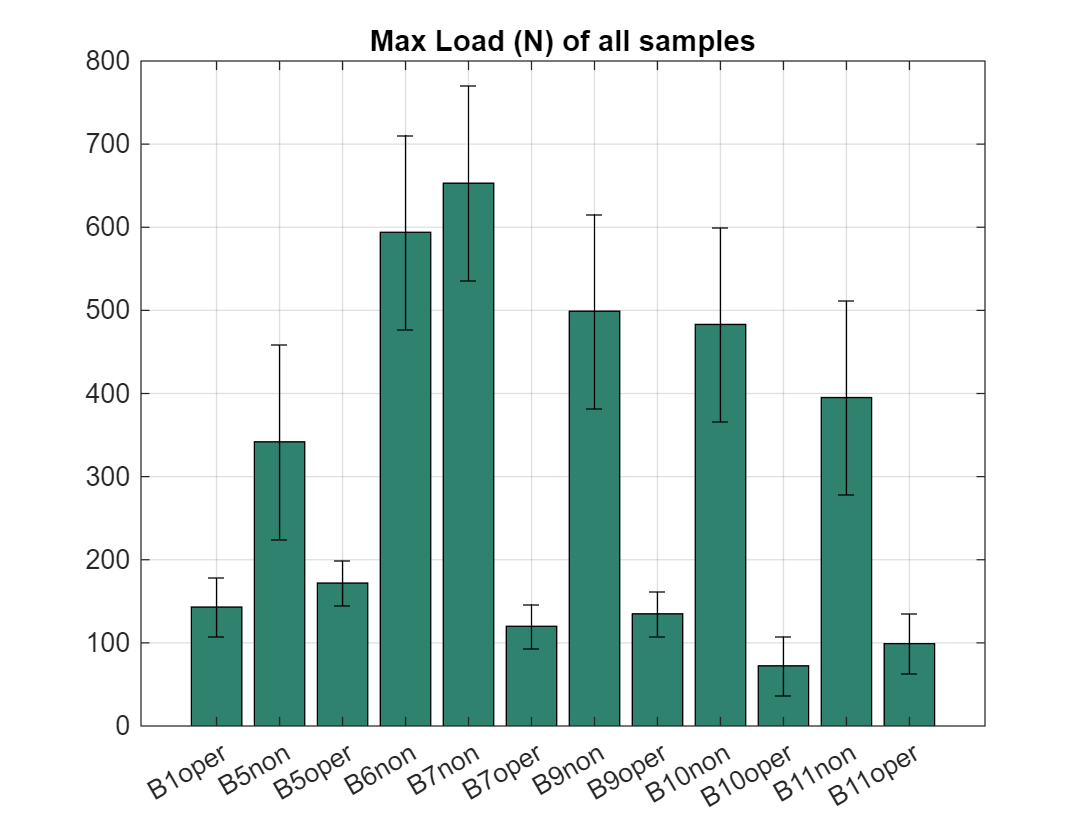

%% Bar plot of all samples
figure( 'Name', 'Max Load (N)_bar' )
bar(MaxLoadN,'FaceAlpha',1.0,'FaceColor', River)
xticklabels(T.Names);
title("Max Load (N) of all samples")
grid on

err = [Failure_load_TFL_std; Failure_load_non_std; Failure_load_MSC_std; 
       Failure_load_non_std; Failure_load_non_std; Failure_load_MSC_std; 
       Failure_load_non_std; Failure_load_MSC_std; Failure_load_non_std; 
       Failure_load_TFL_std; Failure_load_non_std; Failure_load_TFL_std];

hold on

er = errorbar(T.MaxLoadN,err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

#### Create a bar plot based on the experimental data | Non Operated

Create a bar plot that shows the maximum load until failure ; rupture of the tendon ; that can handle each sample, from the group that was not operated.

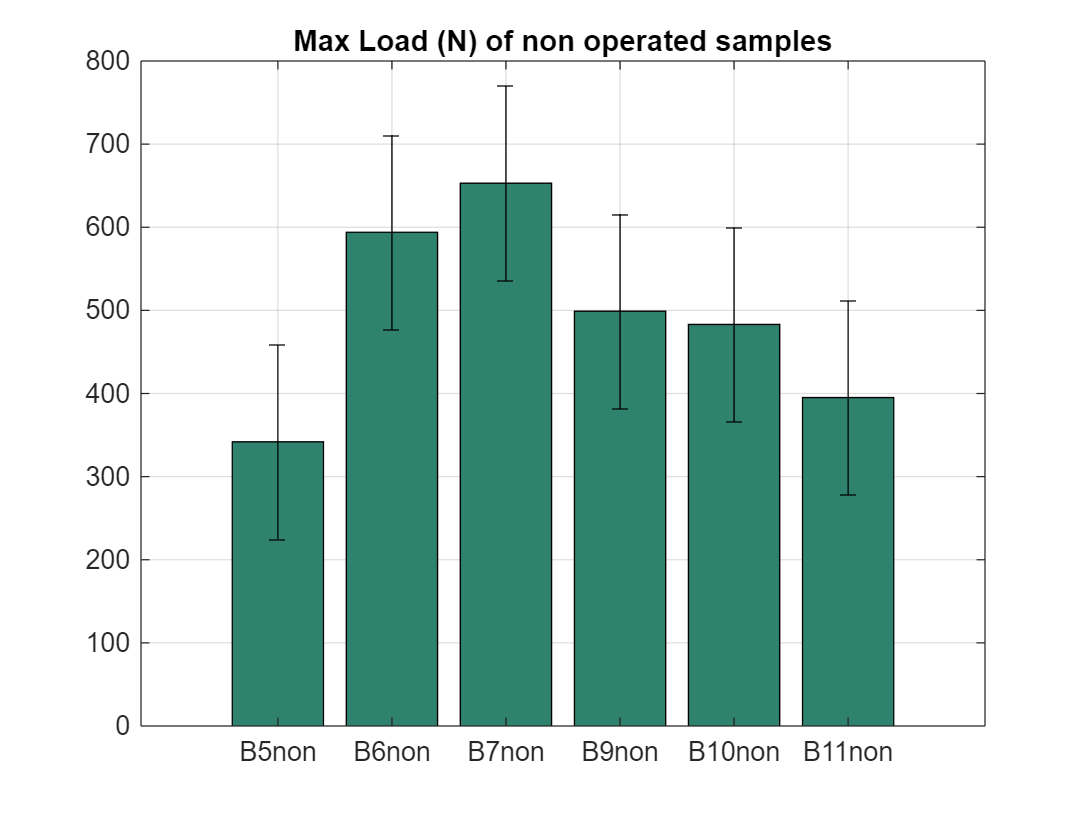

%% Bar plot of Non Operated Samples
figure( 'Name', 'Non Operated Samples_bar' )
bar(T1.MaxLoadN,'FaceAlpha',1.0,'FaceColor', River)
xticklabels(T1.Names);
title("Max Load (N) of non operated samples")
grid on

err = Failure_load_non_std*ones(size(T1.Names));

hold on

er = errorbar(T1.MaxLoadN,err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

#### Create a bar plot based on the experimental data | MSC

Create a bar plot that shows the maximum load until failure ; rupture of the tendon ; that can handle each sample, from the group that was operated with the MSC Method.

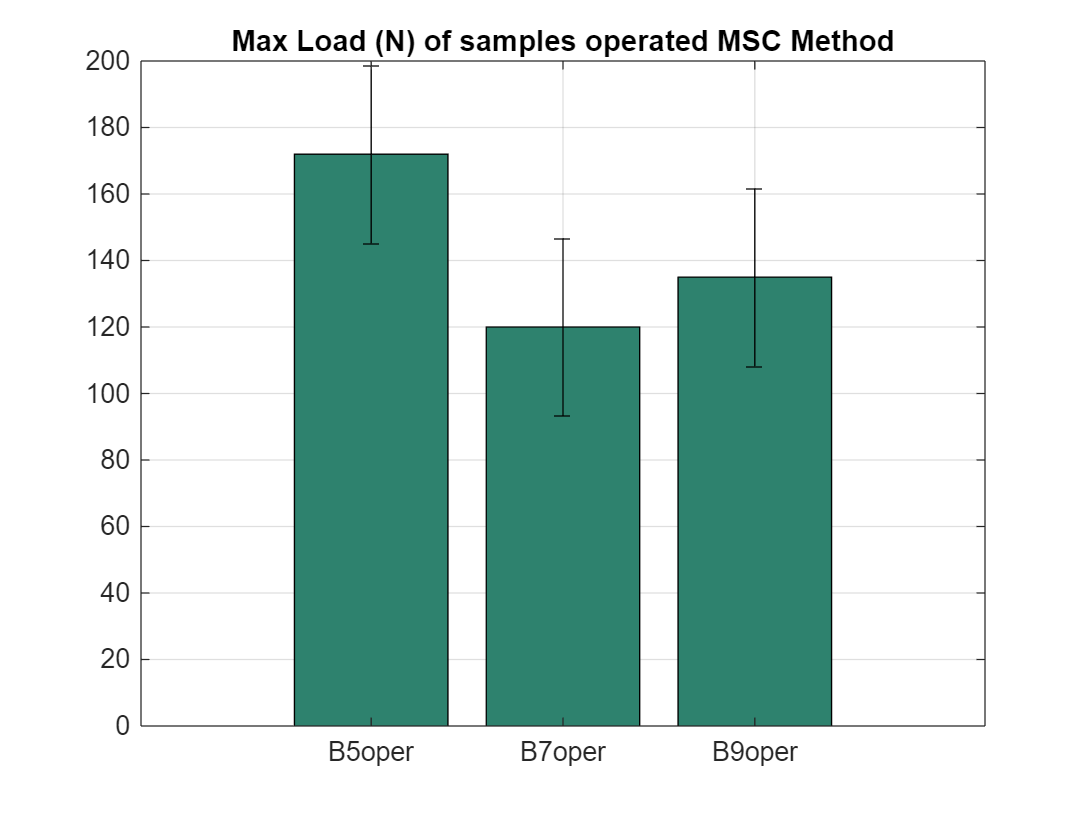

%% Bar plot of Operated Samples | MSC
figure( 'Name', 'Operated with MSC Method_bar' )
bar(T2.MaxLoadN,'FaceAlpha',1.0,'FaceColor', River)
xticklabels(T2.Names);
title("Max Load (N) of samples operated MSC Method")
grid on

err = Failure_load_MSC_std*ones(size(T2.Names));

hold on

er = errorbar(T2.MaxLoadN,err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

#### Create a bar plot based on the experimental data | TFL

Create a bar plot that shows the maximum load until failure ; rupture of the tendon ; that can handle each sample, from the group that was operated with the TFL Method.

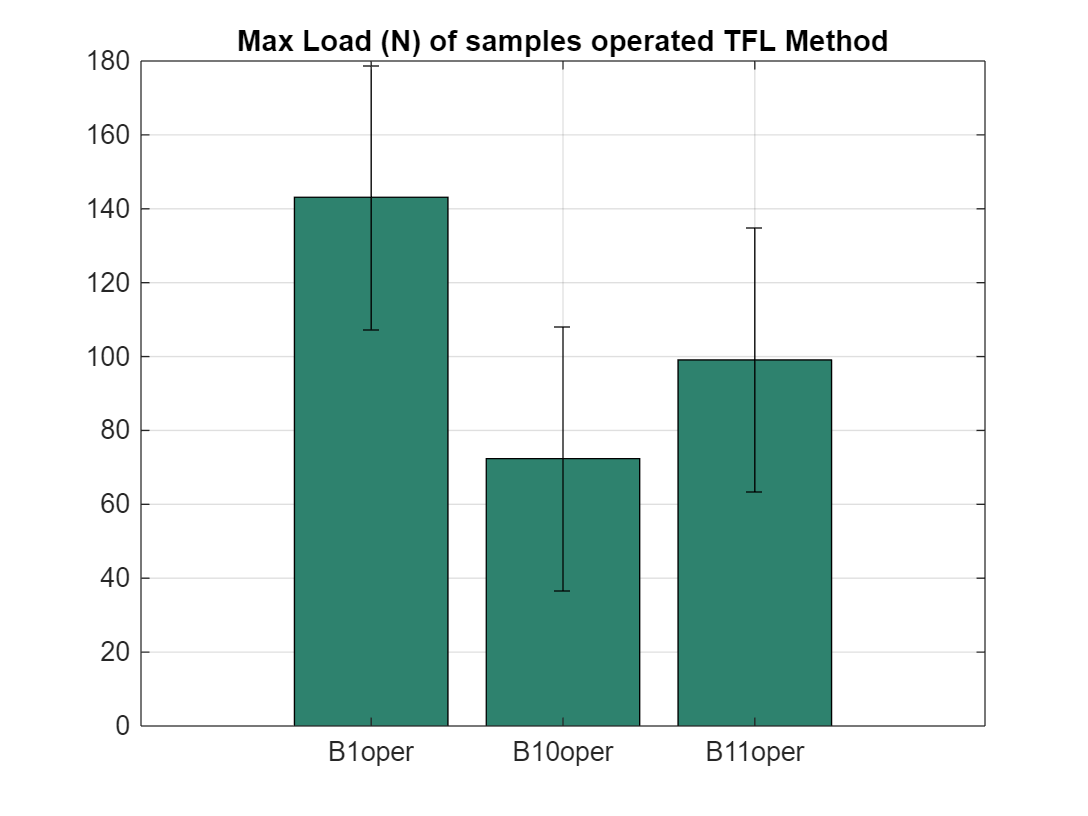

%% Bar plot of Operated Samples | TFL
figure( 'Name', 'Operated with TFL Method_bar' )
bar(T3.MaxLoadN,'FaceAlpha',1.0,'FaceColor', River)
xticklabels(T3.Names);
title("Max Load (N) of samples operated TFL Method")
grid on
err = Failure_load_TFL_std*ones(size(T3.Names));

hold on

er = errorbar(T3.MaxLoadN,err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

#### Create a bar plot based on the experimental data | Groups

Create a bar plot that shows the maximum load until failure ; rupture of the tendon ; that each group can handle .

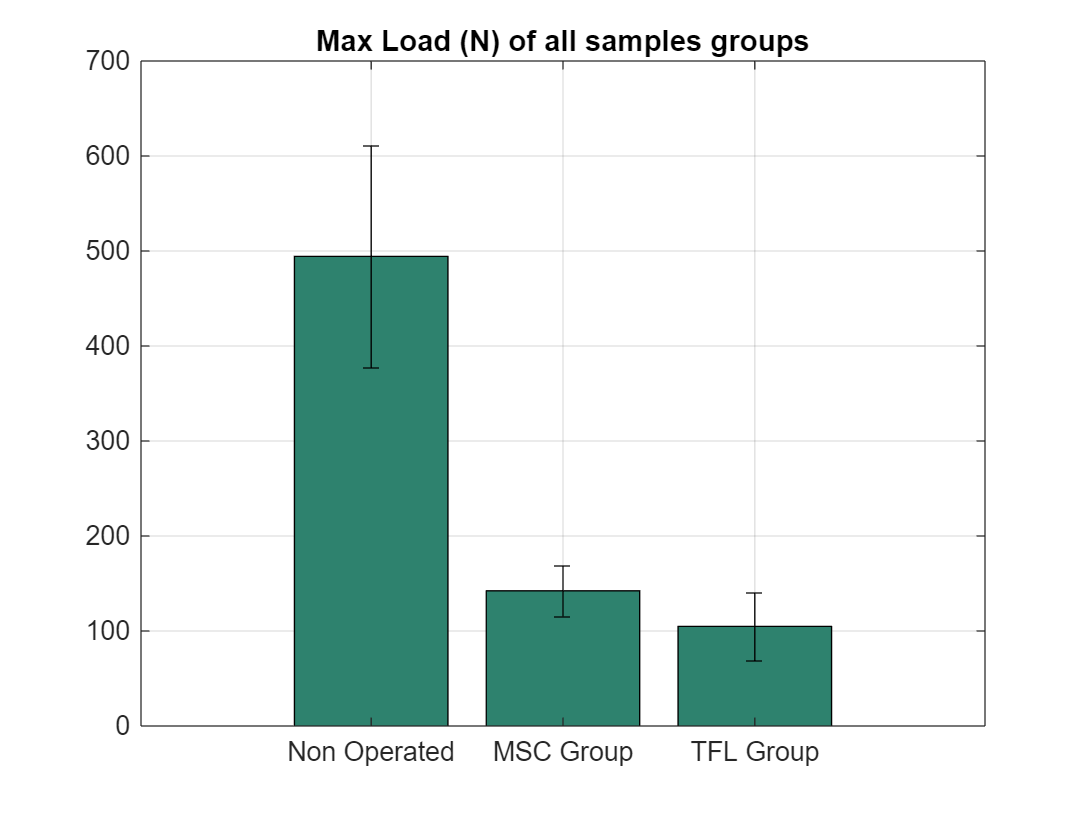

%% Bar plot of Representatives
figure( 'Name', 'All_Groups_bar' )
bar([Failure_load_non_mean; Failure_load_MSC_mean; Failure_load_TFL_mean ],'FaceAlpha',1.0,'FaceColor', River)
xticklabels(["Non Operated","MSC Group","TFL Group"]);
title("Max Load (N) of all samples groups")
grid on
err = [Failure_load_non_std; Failure_load_MSC_std; Failure_load_TFL_std ];

hold on

er = errorbar([Failure_load_non_mean; Failure_load_MSC_mean; Failure_load_TFL_mean],err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

#### Create a bar plot based on the experimental data | Groups

Create a bar plot that shows the stiffness of each group.

%% Bar plot of Representatives
figure( 'Name', 'All_Groups_bar' )
bar([Failure_load_non_mean; Failure_load_MSC_mean; Failure_load_TFL_mean ],'FaceAlpha',1.0,'FaceColor', River)
xticklabels(["Non Operated","MSC Group","TFL Group"]);
title("Max Load (N) of all samples groups")
grid on
err = [Failure_load_non_std; Failure_load_MSC_std; Failure_load_TFL_std ];

hold on

er = errorbar([Failure_load_non_mean; Failure_load_MSC_mean; Failure_load_TFL_mean],err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off

# Comparative Graphs (Abstract)

Plot the force vs. displacement graph on group figures for comparison of the mechanical behaviour of each sample. 

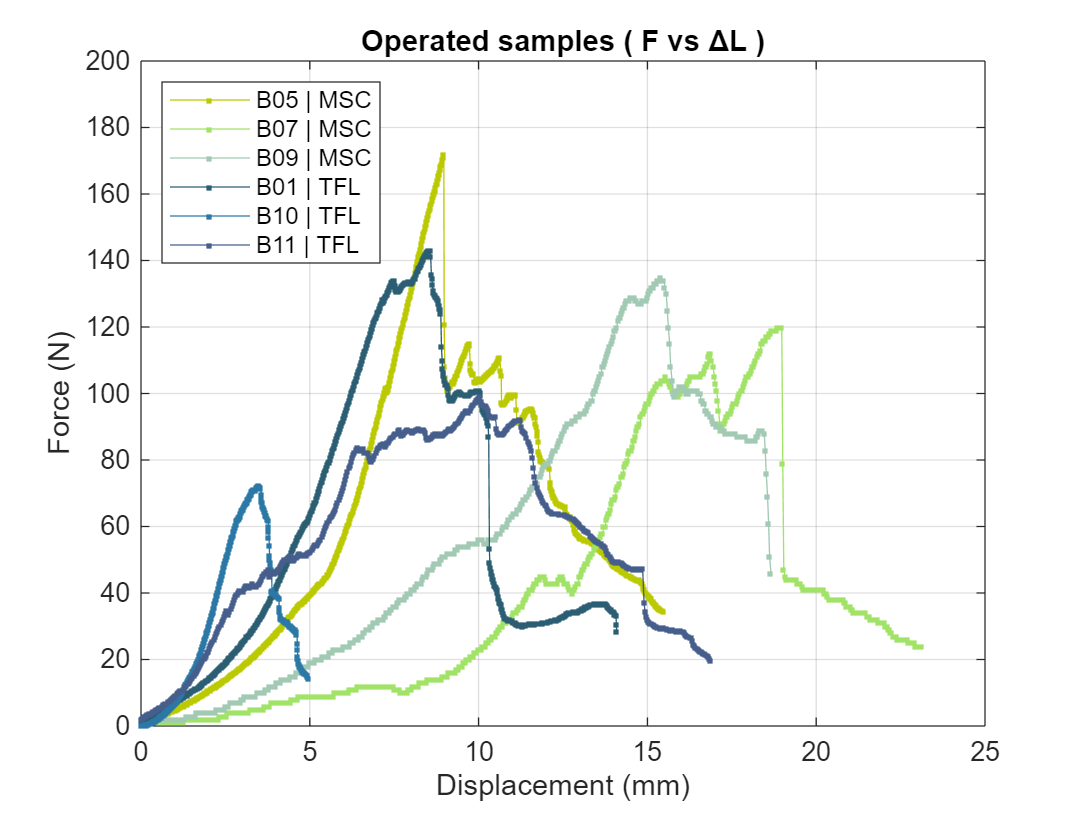

%%  'Operated Samples"
figure( 'Name', 'Operated  Samples | Compared' )

% Plot data
h = plot(B5o_Displacementmm, B5o_LoadN,'Marker','.','LineStyle','-','color', Olive_a); % B5 Operated

hold on

h = plot(B7o_Displacementmm, B7o_LoadN,'Marker','.','LineStyle','-','color', Olive_b); % B7 Operated

h = plot(B9o_Displacementmm, B9o_LoadN,'Marker','.','LineStyle','-','color', Olive_c); % B9 Operated

h = plot(B1o_Displacementmm,  B1o_LoadN, 'Marker','.','LineStyle','-','color', Ocean_a); % B1 Operated

h = plot(B10o_Displacementmm, B10o_LoadN,'Marker','.','LineStyle','-','color', Ocean_b); % B10 Operated

h = plot(B11o_Displacementmm, B11o_LoadN,'Marker','.','LineStyle','-','color', Ocean_c); % B11 Operated

% Legend
legend('B05 | MSC','B07 | MSC','B09 | MSC','B01 | TFL','B10 | TFL','B11 | TFL', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)', 'Interpreter', 'none' );
title("Operated samples ( F vs ΔL )")
grid on

xlim([0 25]) 
ylim([0 200])

hold off

#### Example of operated sample 

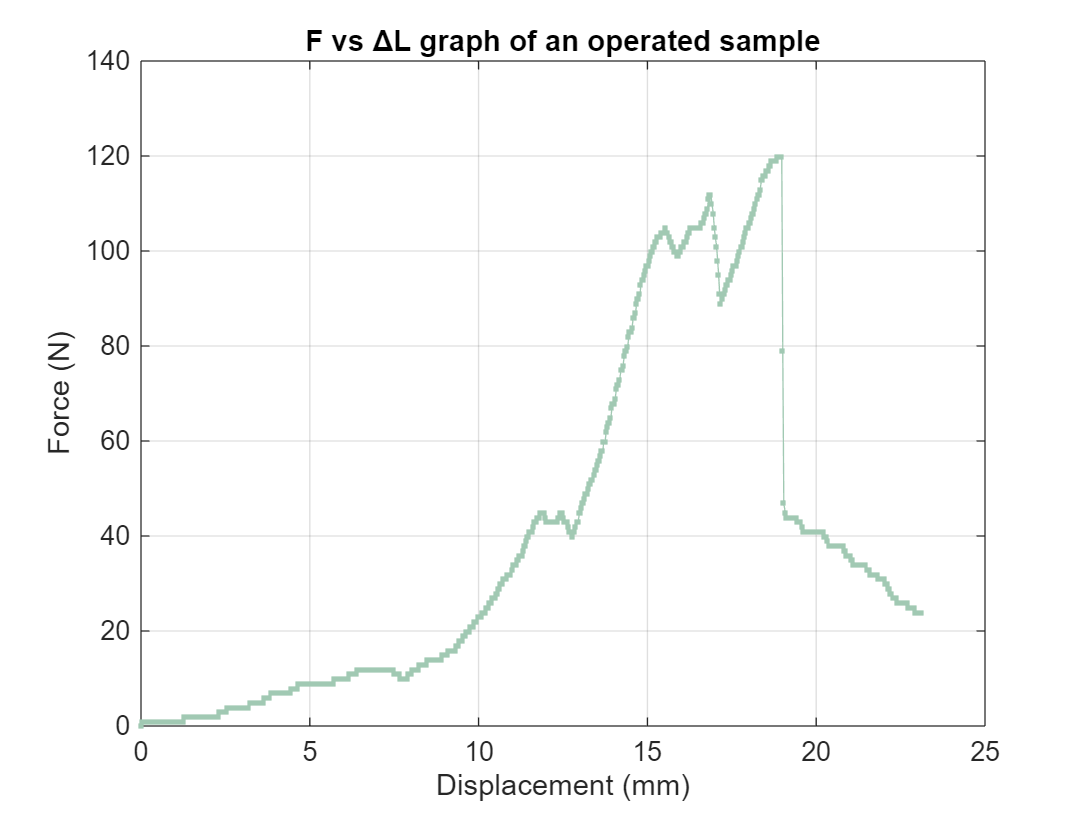

%%  'Operated Sample"
figure( 'Name', 'Operated Sample | Example' )

% Plot data

h = plot(B7o_Displacementmm, B7o_LoadN,'Marker','.','LineStyle','-','color', Olive_c); % B7 Operated

% Legend
%legend('B07 | MSC', 'Location', 'NorthWest', 'Interpreter', 'none' );

% Label axes
xlabel( 'Displacement (mm)', 'Interpreter', 'none' );
ylabel( 'Force (N)', 'Interpreter', 'none' );
title("F vs ΔL graph of an operated sample")
grid on

xlim([0 25]) 
ylim([0 140])

hold off

#### Create a bar plot based on the experimental data | Groups

Create a bar plot that shows the stiffness of each group.

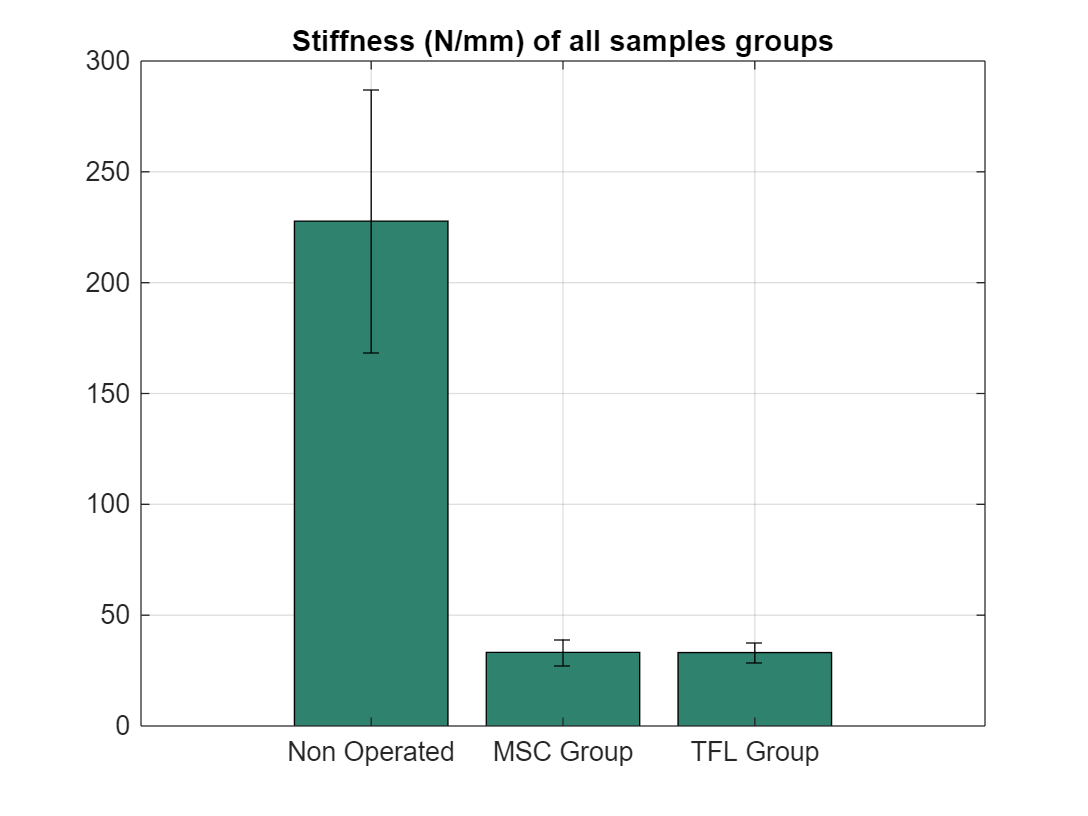

%% Bar plot of Representatives
figure( 'Name', 'All_Groups_bar' )
bar([Stiffness_non_mean; Stiffness_MSC_mean; Stiffness_TFL_mean ],'FaceAlpha',1.0,'FaceColor', River)
xticklabels(["Non Operated","MSC Group","TFL Group"]);
title("Stiffness (N/mm) of all samples groups")
grid on
err = [Stiffness_non_std; Stiffness_MSC_std; Stiffness_TFL_std ];

hold on

er = errorbar([Stiffness_non_mean; Stiffness_MSC_mean; Stiffness_TFL_mean],err);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off